% Initializing script
clc, clf, clear

constants;

% Design space for optimization
n_data = 10;    % number of data points
P_c = linspace(0.5*P_c_ref, 1.5*P_c_ref, n_data); % chamber pressure range (Pa)
A_t = linspace(0.5*A_t_ref, 1.5*A_t_ref, n_data); % throat area range (m2)
A_e = linspace(0.5*A_e_ref, 1.5*A_e_ref, n_data); % exit area range (m2)

## Convexity analysis

% Initializing objective function values
total_mass_P_c = zeros(1, length(P_c)); 
total_mass_A_t = zeros(1, length(A_t));
total_mass_A_e = zeros(1, length(A_e));

% Calculating objective function value w.r.t each design variables
for i = 1:length(P_c)
    total_mass_P_c(i) = calc_objective([P_c(i)/P_c_ref, 1, 1]);
    total_mass_A_t(i) = calc_objective([1, A_t(i)/A_t_ref, 1]);
    total_mass_A_e(i) = calc_objective([1, 1, A_e(i)/A_e_ref]);
end

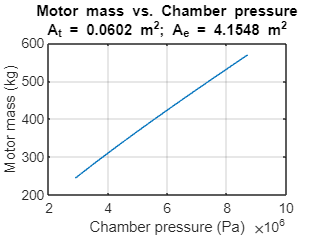

% Plotting results
plot(P_c, total_mass_P_c)
xlabel('Chamber pressure (Pa)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Chamber pressure' 'A_t = 0.0602 m^2; A_e = 4.1548 m^2'})
grid on

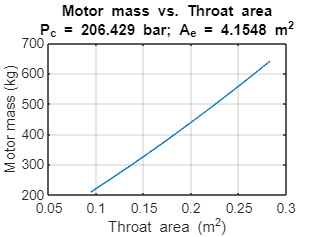


plot(A_t, total_mass_A_t)
xlabel('Throat area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Throat area' 'P_c = 206.429 bar; A_e = 4.1548 m^2'})
grid on

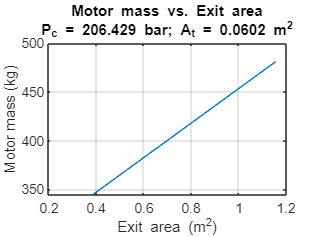


plot(A_e, total_mass_A_e)
xlabel('Exit area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Exit area' 'P_c = 206.429 bar; A_t = 0.0602 m^2'})
grid on

## Calculating objective function in design space

% Initializing objective and constraint function values
total_mass_val = zeros(length(P_c), length(A_t), length(A_e));
ineq_constraint = zeros(length(P_c), length(A_t), length(A_e));
eq_constraint = zeros(length(P_c), length(A_t), length(A_e));

% Calculating objective and constraint functions
for i = 1:length(P_c)
    for j = 1:length(A_t)
        for k = 1:length(A_e)
            x_scaled = scale([P_c(i), A_t(j), A_e(k)], x_ref);
            total_mass_val(i, j, k) = calc_objective(x_scaled);
            [ineq_constraint(i,j,k), eq_constraint(i,j,k)] = calc_constraints(x_scaled);
        end
    end
end

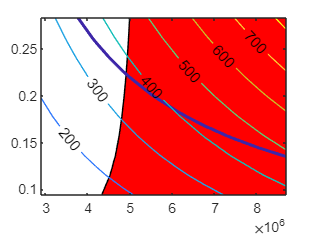

% Example plot
clf
i = 4;
contourf(P_c, A_t, ineq_constraint(:, :, i), [0,0], 'FaceColor', '#FF0000');
hold on
[M,c] = contour(P_c, A_t, eq_constraint(:, :, i), [0,0]);
c.LineWidth = 2;
contour(P_c, A_t, total_mass_val(:,:, i), 'ShowText','on')
hold off

%% Sample SQP conditions
% Linear constraints
A = []; 
b = [];
Aeq = [];
beq = [];

% Design variable bounds
lb = [0.1, 0.1, 0.1];
ub = [10, 10, 10];

options = optimoptions('fmincon','Display','iter','Algorithm','sqp');
x0 = [1, 1, 1];
[x, fval, exitflag, output, lambda] = fmincon(@calc_objective_test, x0, ...
    A, b, Aeq, beq, lb, ub, @calc_constraints, options)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    3.843998e+03     2.220e-16     1.000e+00     0.000e+00     3.248e+03  
    1           8    1.002808e+03     8.259e-01     1.000e+00     1.610e+00     3.586e+02  
    2          14    1.920427e+03     3.180e-01     4.900e-01     2.129e+00     2.593e+02  
    3          19    2.026556e+03     3.022e-01     7.000e-01     2.731e+00     7.722e+02  
    4          23    1.664226e+03     5.863e-01     1.000e+00     4.273e+00     1.338e+03  
    5          27    2.438795e+03     6.311e-02     1.000e+00     1.806e+00     1.205e+02  
    6          31    2.351627e+03     2.204e-02     1.000e+00     1.250e+00     9.672e+01  
    7          35    2.402601e+03     1.534e-02     1.000e+00     4.111e-01     1.583e+02  
    8          39    2.424005e+03     9.531e-05     1.000e+00     1.156e-01     3.

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 51
          algorithm: 'sqp'
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 4.532791e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 4.174223e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
    constrviolation: 4.1742e-10
           stepsize: 1.5212e-04
       lssteplength: 1
      firstorderopt: 0.0023
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03
         lower: [3×1 double]
         upper: [3×1 double]


x = descale(x, x_ref);
fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f\nTotal Mass = %f' ...
    , x(1), x(2), x(3), fval)

Chamber pressure = 1869322.621655
Throat area = 0.585175
Exit area = 3.203538
Total Mass = 2424.058376

options = optimoptions('fmincon','Display','iter','Algorithm','active-set');
tic
for i=1:100
x0 = lb + rand(size(lb)).*(ub - lb);
[x, fval, exitflag, output, lambda] = fmincon(@calc_objective_test, x0, ...
    A, b, Aeq, beq, lb, ub, @calc_constraints, options)
x = descale(x, x_ref);
fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f\nTotal Mass = %f' ...
    , x(1), x(2), x(3), fval)
if(i==1)
    fvalref=output.bestfeasible.fval;
    ssq=0
end
ssq=ssq+abs(output.bestfeasible.fval-fvalref);
end


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      49151.3         45.2                                         Infeasible start point
    1      8      16818.1        3.362            1    -4.29e+03     3.16e+04   
    2     12      881.931       0.9079            1    -2.85e+03     1.88e+04   
    3     16      3612.08       0.2631            1          131     1.72e+04   
    4     20      2478.96       0.1986            1         -279     1.46e+04   
    5     24      1960.96       0.3467            1        -56.2     3.54e+04   
    6     28      2586.26      0.04105            1          551          760   
    7     32      2525.18      0.01077            1        -97.1          858  Hessian modified  
    8     36      2490.34      0.00168            1        -39.3          380   
    9     46      2486.47     0.001677       0.0156        -51.5

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 4

output = struct with fields:
         iterations: 24
          funcCount: 138
       lssteplength: 1
           stepsize: 3.1411e-07
          algorithm: 'active-set'
      firstorderopt: 1.2498e-05
    constrviolation: 1.1432e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 2.871328e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.143152e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869335.477845
Throat area = 0.585171
Exit area = 3.203501
Total Mass = 2424.058377

ssq = 0


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4        13824        2.688                                         Infeasible start point
    1      8      887.029       0.9287            1    -2.34e+03          484   
    2     12      2902.25       0.1292            1         99.6     7.75e+03   
    3     17      2078.56       0.3198          0.5         -126     1.76e+03   
    4     21      2507.97      0.03602            1          895     1.25e+03   
    5     26      2397.22      0.03567          0.5        -47.5          892   
    6     32       2353.7      0.03734         0.25        -34.5          223   
    7     36      2370.32      0.03436            1         43.4         5.92   
    8     40      2423.92    6.531e-05            1          232           17   
    9     44      2424.02    2.235e-05            1         3.67         4.08   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 52
       lssteplength: 1
           stepsize: 7.9254e-06
          algorithm: 'active-set'
      firstorderopt: 7.6314e-04
    constrviolation: 7.6250e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.106528e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 7.625012e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869333.323464
Throat area = 0.585171
Exit area = 3.203507
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4        44431         38.7                                         Infeasible start point
    1      8      1748.23       0.5012            1    -5.53e+03      9.9e+04   
    2     12      1332.02       0.9726            1         27.8     2.74e+03   
    3     16      2176.76       0.1226            1         44.5          183   
    4     20      2402.02       0.0101            1          228          127   
    5     24       2384.2      0.02511            1        0.345          163   
    6     28      2417.87     0.002884            1         73.4         2.38   
    7     32      2423.96    6.496e-05            1          213         1.39   
    8     36      2424.06    7.766e-09            1          211       0.0191   
    9     40      2424.06    2.094e-13            1          3.6      0.00154  He

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 10
          funcCount: 40
       lssteplength: 1
           stepsize: 3.8016e-06
          algorithm: 'active-set'
      firstorderopt: 8.2317e-05
    constrviolation: 2.0939e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.817266e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 2.093881e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869328.429449
Throat area = 0.585173
Exit area = 3.203522
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      22496.6        15.03                                         Infeasible start point
    1      8      1237.02       0.7031            1    -3.86e+03      1.4e+04   
    2     12      2252.62       0.3955            1          392     1.37e+03   
    3     16      1914.44       0.9618            1        -73.6     2.82e+03   
    4     20      1117.55       0.8385            1        -79.4     1.34e+03   
    5     24      2356.93       0.3613            1          396          761   
    6     28       2458.6      0.06467            1          106     1.68e+03   
    7     32      2415.08      0.02666            1        -44.1          833   
    8     37      2390.97      0.02378          0.5          -31         77.1   
    9     41      2415.52     0.004437            1         52.8         53.9   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 14
          funcCount: 57
       lssteplength: 1
           stepsize: 2.3993e-05
          algorithm: 'active-set'
      firstorderopt: 0.0033
    constrviolation: 3.6740e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵3.565232e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 3.673961e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869335.927848
Throat area = 0.585170
Exit area = 3.203500
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      32931.5        22.81                                         Infeasible start point
    1      8      1603.49       0.5443            1    -4.74e+03     6.34e+04   
    2     12      1408.53       0.9709            1         74.2     9.92e+03   
    3     16      1413.43       0.7313            1        -10.7     3.16e+04   
    4     20      3123.54       0.2642            1          807     3.71e+03   
    5     25       2555.3       0.1018          0.5         -118     2.29e+03  Hessian modified twice  
    6     29       2302.1      0.09355            1         -113          160   
    7     33       2420.4     0.002632            1          205         45.3   
    8     37      2424.06    1.169e-06            1          419         1.93   
    9     41      2424.06    2.215e-08            1       

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 14
          funcCount: 61
       lssteplength: 1
           stepsize: 1.4530e-05
          algorithm: 'active-set'
      firstorderopt: 0.0036
    constrviolation: 8.6038e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.932417e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 8.603784e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869319.604810
Throat area = 0.585175
Exit area = 3.203547
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      16728.3        8.424                                         Infeasible start point
    1      8      1263.22       0.7982            1    -2.04e+03          643   
    2     12      1625.68        0.971            1          212      2.8e+03   
    3     16      1271.84          0.8            1        -16.3     1.65e+03   
    4     20      1942.88       0.5172            1          169          882   
    5     25       1724.6       0.4746          0.5        -60.1     1.22e+03   
    6     29      2499.81      0.08622            1          694     1.47e+03   
    7     33      2440.47      0.01565            1         -104         69.6  Hessian modified  
    8     37      2456.32    0.0002881            1          116         71.1   
    9     46      2454.85    0.0002952       0.0312        -70.6

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 27
          funcCount: 166
       lssteplength: 1
           stepsize: 7.9559e-05
          algorithm: 'active-set'
      firstorderopt: 0.0016
    constrviolation: 6.4374e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.668552e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 6.437439e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869324.557561
Throat area = 0.585174
Exit area = 3.203533
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      48571.8        57.73                                         Infeasible start point
    1      8      21514.5       0.2273            1    -2.56e+03      4.4e+04   
    2     14      16204.5       0.2349         0.25    -2.49e+03      1.4e+04   
    3     20      12819.4       0.2421         0.25    -1.73e+03     3.08e+04   
    4     25      6655.58       0.3733          0.5    -1.85e+03      4.1e+03   
    5     30      4235.04       0.4387          0.5         -584     3.16e+03   
    6     34       2960.2       0.3363            1         -802      2.7e+03   
    7     38      3366.22      0.02164            1          401     1.49e+03   
    8     43         2434       0.1171          0.5         -289          954  Hessian modified twice  
    9     47      2366.23      0.05174            1       

x =     0.3223    3.1027    4.1614


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 16
          funcCount: 71
       lssteplength: 1
           stepsize: 3.6123e-05
          algorithm: 'active-set'
      firstorderopt: 0.0057
    constrviolation: 7.8040e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵3.994329e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 7.804035e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3423e+03


Chamber pressure = 1869342.492736
Throat area = 0.585168
Exit area = 3.203481
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      21682.7        16.63                                         Infeasible start point
    1      8      1545.72       0.5774            1    -4.62e+03     3.09e+04   
    2     12      1426.35       0.9694            1         81.9     2.74e+03   
    3     16      1982.75       0.2486            1         19.7          245   
    4     20      2422.37      0.01011            1          370          160   
    5     24      2417.73     0.005073            1        -6.16         26.6   
    6     28      2423.08    0.0004673            1         35.6         25.5   
    7     32      2424.04    9.181e-06            1           56        0.378   
    8     36      2424.06    1.275e-09            1         52.3       0.0023   
    9     40      2424.06    5.708e-12            1        0.285      0.00258  He

x =     0.3223    3.1027    4.1616


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 10
          funcCount: 40
       lssteplength: 1
           stepsize: 8.7586e-06
          algorithm: 'active-set'
      firstorderopt: 0.0022
    constrviolation: 5.7078e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵3.609674e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 5.707768e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869313.613053
Throat area = 0.585177
Exit area = 3.203565
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      21562.4        12.64                                         Infeasible start point
    1      8      1300.33       0.6787            1    -3.45e+03     3.45e+04   
    2     12      1657.76       0.9599            1          250     1.87e+03   
    3     16      1206.89       0.7839            1        -63.1     1.43e+03   
    4     20      1901.57       0.7401            1          234     1.95e+03   
    5     25      1691.62       0.5682          0.5        -61.5          332   
    6     29      3057.69       0.1907            1          320      1.2e+03   
    7     34      2617.89      0.03722          0.5         -512     1.17e+03  Hessian modified  
    8     38      2424.77      0.01913            1         -185          450   
    9     42      2424.58     0.003449            1          5.4

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 15
          funcCount: 63
       lssteplength: 1
           stepsize: 2.4238e-05
          algorithm: 'active-set'
      firstorderopt: 8.6751e-04
    constrviolation: 3.5708e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵7.449971e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 3.570844e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869320.331687
Throat area = 0.585175
Exit area = 3.203545
Total Mass = 2424.058376


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      32477.3        36.34                                         Infeasible start point
    1      8      15497.5        0.474            1    -1.22e+03     4.12e+04   
    2     13       8003.4       0.4903          0.5    -1.92e+03     6.55e+03   
    3     18       5083.7       0.4857          0.5         -741     1.71e+04   
    4     22      3645.66        0.428            1         -189     2.82e+03   
    5     26       904.27       0.8941            1    -1.34e+03          321   
    6     30      3349.71      0.05907            1     2.27e+03     1.67e+03   
    7     34      3402.72      0.01332            1          154     1.86e+03   
    8     38      3297.81     0.004812            1         -497     1.44e+03   
    9     43      2966.41      0.02955          0.5         -926          880   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 23
          funcCount: 108
       lssteplength: 1
           stepsize: 1.4803e-05
          algorithm: 'active-set'
      firstorderopt: 0.0040
    constrviolation: 1.2042e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.960416e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.204170e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869315.892384
Throat area = 0.585177
Exit area = 3.203558
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      19641.1        15.66                                         Infeasible start point
    1      8      1476.53       0.6057            1    -3.11e+03     9.96e+03   
    2     12      1469.48       0.9679            1          106     2.76e+03   
    3     16      1321.07       0.6563            1        -69.2          215   
    4     20      2383.67       0.4198            1          308     1.45e+03   
    5     24      1950.88       0.2549            1         -149          804   
    6     28      2311.09      0.05585            1          377          250   
    7     32      2421.66     0.001546            1          340         13.4   
    8     36      2423.45    0.0004893            1         12.3         12.6   
    9     40      2423.42    0.0003312            1          1.6        0.256   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 1.1633e-05
          algorithm: 'active-set'
      firstorderopt: 4.6341e-04
    constrviolation: 5.3936e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵8.493480e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 5.393590e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869334.738813
Throat area = 0.585171
Exit area = 3.203503
Total Mass = 2424.058376


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      38145.2        46.38                                         Infeasible start point
    1      8      16548.4       0.4552            1    -1.15e+03     8.76e+04   
    2     13      8465.85       0.4804          0.5    -1.77e+03     7.17e+03   
    3     17      9490.13      0.03522            1          129     3.31e+04   
    4     22      7277.65      0.05421          0.5         -459     4.11e+03   
    5     27       5506.2      0.09563          0.5         -711     4.36e+03   
    6     32      4212.74       0.1851          0.5         -452      2.5e+03   
    7     37      3632.25       0.1296          0.5         -229     2.84e+03   
    8     42      3129.99       0.1205          0.5         -415     1.27e+03   
    9     47      2337.08       0.2854          0.5         -267          434   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 19
          funcCount: 86
       lssteplength: 1
           stepsize: 4.2694e-06
          algorithm: 'active-set'
      firstorderopt: 2.2842e-04
    constrviolation: 1.0739e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.407219e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.073919e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869325.890214
Throat area = 0.585174
Exit area = 3.203529
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      3967.59         0.32                                         Infeasible start point
    1      9      2668.05      0.03862          0.5    -1.49e+03      1.1e+03   
    2     16      2553.48      0.04469        0.125         -342          796  Hessian modified  
    3     23      2463.68      0.04955        0.125         -236     1.15e+03  Hessian modified  
    4     31      2431.52      0.04895       0.0625         -153          762   
    5     39      2404.51      0.04833       0.0625         -120          548   
    6     47      2382.46      0.04769       0.0625        -90.9          511   
    7     55      2365.23      0.04702       0.0625        -65.3          467   
    8     62      2351.09      0.04518        0.125        -32.5          347   
    9     66      2361.86      0.03828         

x =     0.3223    3.1030    4.1620


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 15
          funcCount: 87
       lssteplength: 0.5000
           stepsize: 2.9539e-04
          algorithm: 'active-set'
      firstorderopt: 0.0017
    constrviolation: 6.7280e-09
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵5.624088e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 6.727960e-09, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3423e+03


Chamber pressure = 1869188.518583
Throat area = 0.585217
Exit area = 3.203928
Total Mass = 2424.058371


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      9291.22        6.044                                         Infeasible start point
    1      8      1575.81       0.5666            1    -1.51e+03     1.45e+03   
    2     12      2455.85       0.1253            1          333     1.34e+03  Hessian modified  
    3     16      2318.01      0.06527            1          -65     4.18e+03   
    4     20      2398.84      0.04233            1         53.7          219   
    5     24      2478.69     0.008228            1          189          269   
    6     28      2484.32    0.0001836            1         41.9         69.8   
    7     41      2483.99    0.0001835      0.00195        -49.8          307   
    8     54      2483.67    0.0001833      0.00195        -49.7          252   
    9     66      2483.03    0.0001834      0.00391        -49.6

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 23
          funcCount: 161
       lssteplength: 1
           stepsize: 2.8925e-06
          algorithm: 'active-set'
      firstorderopt: 1.6701e-04
    constrviolation: 1.6986e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵5.686587e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.698641e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869329.110391
Throat area = 0.585173
Exit area = 3.203520
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      23580.2        23.51                                         Infeasible start point
    1      8      11438.2        1.166            1    -1.11e+03     3.02e+03   
    2     12      980.938       0.9776            1    -2.02e+03      1.1e+03  Hessian modified  
    3     16       2639.6       0.2087            1          126          427  Hessian modified twice  
    4     20      1292.12       0.8081            1         -117     1.52e+03   
    5     24      1660.98       0.5212            1          101     2.14e+03   
    6     28      2411.85      0.03789            1          423     1.68e+03   
    7     32      1677.74       0.9608            1        -72.1     2.81e+03   
    8     36      1124.43       0.7596            1         -159     1.78e+03   
    9     40      2521.93      0.07053   

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 17
          funcCount: 70
       lssteplength: 1
           stepsize: 1.2622e-05
          algorithm: 'active-set'
      firstorderopt: 4.5800e-04
    constrviolation: 1.2999e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.647521e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.299932e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869326.630950
Throat area = 0.585173
Exit area = 3.203527
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      42231.7        11.08                                         Infeasible start point
    1      8      888.721       0.9279            1    -4.02e+03     1.37e+03   
    2     12      3632.37       0.3515            1          121     2.07e+04   
    3     17      2393.01       0.1004          0.5         -225      1.2e+03   
    4     21      2662.08      0.03397            1         86.8     6.34e+03   
    5     25      2715.62      0.01549            1          135     8.98e+04   
    6     29      2639.23     0.001432            1        -51.5          972   
    7     35      2497.09     0.005429         0.25        -66.3     1.71e+03   
    8     39      2460.52      0.00209            1        -44.3     3.39e+03   
    9     44      2444.46     0.002312          0.5        -37.9          734   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 17
          funcCount: 74
       lssteplength: 1
           stepsize: 7.7577e-06
          algorithm: 'active-set'
      firstorderopt: 4.5819e-04
    constrviolation: 1.3950e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵4.352678e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.394962e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869314.980611
Throat area = 0.585177
Exit area = 3.203561
Total Mass = 2424.058376


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      6701.68        1.686                                         Infeasible start point
    1      8      1042.46       0.8022            1    -2.98e+03     7.76e+03   
    2     12      3267.98       0.4289            1          240     4.03e+03   
    3     16      1847.32       0.4582            1         -247     2.54e+03   
    4     21      1672.76       0.4632          0.5           19          336   
    5     25      2413.89      0.05234            1          705          310   
    6     29      2362.14      0.04873            1        -37.2          278  Hessian modified  
    7     33      2432.39    0.0004719            1          349          202   
    8     38      2427.71    0.0002501          0.5        -32.4          193   
    9     45      2426.81    0.0002645        0.125        -19.9

x =     0.3223    3.1028    4.1616


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 17
          funcCount: 82
       lssteplength: 0.5000
           stepsize: 8.1669e-05
          algorithm: 'active-set'
      firstorderopt: 0.0057
    constrviolation: 5.8052e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵5.589362e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 5.805250e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3423e+03


Chamber pressure = 1869305.075971
Throat area = 0.585180
Exit area = 3.203589
Total Mass = 2424.058376


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      22392.4        2.799                                         Infeasible start point
    1      8      835.083       0.9552            1    -3.17e+03          638   
    2     12      7521.57        3.536            1          233     4.33e+04   
    3     16      2204.64       0.9707            1         -684     2.08e+04  Hessian modified twice  
    4     20      1126.53       0.8928            1          -43     7.96e+03   
    5     24      2518.33       0.3584            1          193     2.41e+03   
    6     28      1001.39       0.8701            1         -287         25.4   
    7     32      3084.85       0.4834            1          707      2.4e+03   
    8     36       2397.5      0.01311            1         -835          171  Hessian modified  
    9     40      2444.98     0.004583   

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 16
          funcCount: 64
       lssteplength: 1
           stepsize: 5.9994e-06
          algorithm: 'active-set'
      firstorderopt: 2.5783e-04
    constrviolation: 9.6682e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.234362e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 9.668166e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869326.984782
Throat area = 0.585173
Exit area = 3.203526
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      32364.4        12.55                                         Infeasible start point
    1      8      957.824       0.8981            1       -4e+03     1.27e+03   
    2     12      4967.09        1.263            1          214     1.29e+04   
    3     16      1542.04       0.9946            1         -430     1.21e+04  Hessian modified twice  
    4     20      1320.27       0.7804            1         49.2     2.16e+04   
    5     24      2294.03       0.4221            1          125     2.57e+03   
    6     28      1161.47       0.7759            1         -201          959   
    7     32      2865.84         0.36            1          625     2.49e+03   
    8     36      2427.02      0.01068            1         -353           36  Hessian modified  
    9     40      2430.94     0.009346   

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 15
          funcCount: 60
       lssteplength: 1
           stepsize: 2.1218e-05
          algorithm: 'active-set'
      firstorderopt: 0.0014
    constrviolation: 6.4498e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵8.084606e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 6.449830e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869323.168847
Throat area = 0.585174
Exit area = 3.203537
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      30851.3        30.96                                         Infeasible start point
    1      8      13298.9       0.5208            1    -2.61e+03      1.6e+04   
    2     13      7013.08       0.5156          0.5    -2.38e+03     5.42e+03   
    3     18      4364.78       0.5133          0.5         -654     2.71e+03   
    4     23       3019.6       0.4917          0.5         -462     3.55e+03   
    5     27      4374.29      0.09858            1          491     2.64e+03   
    6     32      2816.55       0.1561          0.5         -639     1.12e+03  Hessian modified  
    7     36      2586.79      0.07339            1         -151          702   
    8     41      2414.45      0.06154          0.5         -114          144   
    9     45      2385.99     0.008355            1        -18.3

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 4

output = struct with fields:
         iterations: 17
          funcCount: 76
       lssteplength: 1
           stepsize: 1.1197e-07
          algorithm: 'active-set'
      firstorderopt: 5.4156e-06
    constrviolation: 4.1821e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.023372e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 4.182099e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869322.726140
Throat area = 0.585175
Exit area = 3.203538
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      8617.11        4.197                                         Infeasible start point
    1      8       1220.3        0.711            1     -3.3e+03        3e+03   
    2     12      2333.64       0.3991            1          397     1.46e+03   
    3     16      1960.96       0.9559            1        -79.8     2.79e+03   
    4     20      1085.59       0.8382            1         -120     1.36e+03   
    5     24      2580.48      0.05411            1          582          641   
    6     28      2644.42     0.008275            1         89.6          428  Hessian modified  
    7     32      2661.76    0.0004755            1          105          513   
    8     36      2661.63    5.295e-06            1         -8.1          518   
    9     40      2539.47      0.01937            1         -167

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 17
          funcCount: 68
       lssteplength: 1
           stepsize: 1.1307e-05
          algorithm: 'active-set'
      firstorderopt: 8.6021e-04
    constrviolation: 9.5610e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.048243e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 9.560996e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869319.523023
Throat area = 0.585176
Exit area = 3.203547
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      38325.1        35.63                                         Infeasible start point
    1      8      12336.6       0.5421            1    -3.09e+03     1.83e+04   
    2     13      9132.53       0.3996          0.5    -2.69e+03     2.98e+03  Hessian modified  
    3     19      7108.17       0.3611         0.25    -2.86e+03     6.05e+03   
    4     24      4065.48       0.4169          0.5    -2.75e+03     2.78e+03  Hessian modified  
    5     29      2611.43       0.4292          0.5    -1.58e+03     1.48e+03   
    6     34      1997.53        0.412          0.5         -385          590   
    7     38      2549.22      0.01679            1          223          494   
    8     42      2493.82     0.004543            1         -178          520   
    9     47      2470.22     0.008723         

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 29
          funcCount: 179
       lssteplength: 1
           stepsize: 1.6632e-05
          algorithm: 'active-set'
      firstorderopt: 0.0023
    constrviolation: 1.2070e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.285756e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.206990e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869326.892088
Throat area = 0.585173
Exit area = 3.203526
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      64063.7        44.35                                         Infeasible start point
    1      8      1450.37       0.6862            1    -6.32e+03     3.97e+05   
    2     12      1635.73       0.8066            1          208     4.53e+03   
    3     16      2915.07       0.2735            1          328          588   
    4     20      2505.98       0.9368            1         -117     2.87e+03   
    5     24      938.644       0.8716            1         -822     1.47e+03   
    6     28      3326.07       0.5418            1      1.7e+03     2.36e+03   
    7     33      2535.62       0.1136          0.5         -648         93.1  Hessian modified twice  
    8     37      2393.97     0.006535            1         -176           92   
    9     41      2421.42    0.0005459            1       

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 14
          funcCount: 57
       lssteplength: 1
           stepsize: 6.6911e-05
          algorithm: 'active-set'
      firstorderopt: 0.0012
    constrviolation: 4.9142e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵4.378429e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 4.914236e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869319.148862
Throat area = 0.585176
Exit area = 3.203549
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      13295.3         8.68                                         Infeasible start point
    1      8      4201.66       0.8743            1    -1.06e+03     2.84e+03   
    2     13      2603.74       0.6668          0.5    -1.97e+03     1.07e+03   
    3     18      1906.88       0.5399          0.5         -614          875   
    4     22      2585.58      0.06058            1          295          904   
    5     26      2531.38    0.0004512            1         -344     1.18e+03   
    6     33       2519.9     0.000699        0.125         -159     1.19e+03   
    7     41      2505.59     0.001172       0.0625         -147          381   
    8     52      2504.12     0.001169      0.00781         -131          395   
    9     63      2502.66     0.001167      0.00781         -130          394   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 29
          funcCount: 217
       lssteplength: 1
           stepsize: 5.9607e-05
          algorithm: 'active-set'
      firstorderopt: 0.0015
    constrviolation: 3.3298e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.016601e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 3.329781e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869328.289836
Throat area = 0.585173
Exit area = 3.203522
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      25428.3        19.27                                         Infeasible start point
    1      8      7858.38        2.712            1    -2.41e+03     1.56e+04   
    2     12      1052.54       0.8009            1    -1.85e+03     9.91e+03   
    3     16      3288.85       0.2393            1          174      1.3e+03   
    4     20      1545.58       0.5574            1         -242         89.3   
    5     24      2567.45       0.1505            1          512          468   
    6     28      2386.91      0.02452            1         -198          386  Hessian modified  
    7     32      2425.11    0.0001536            1          444         20.2   
    8     37      2424.52    2.278e-05          0.5        -11.1         60.3   
    9     43      2424.27    1.138e-05         0.25        -6.67

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 15
          funcCount: 66
       lssteplength: 1
           stepsize: 1.2922e-05
          algorithm: 'active-set'
      firstorderopt: 0.0018
    constrviolation: 1.8888e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵3.949510e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.888822e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869332.200818
Throat area = 0.585172
Exit area = 3.203511
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      46575.3        45.83                                         Infeasible start point
    1      8      17809.3       0.3251            1    -3.96e+03     3.09e+04   
    2     13        10834       0.3555          0.5    -2.91e+03     3.38e+03  Hessian modified  
    3     19      8382.28       0.3286         0.25    -2.89e+03     7.38e+03   
    4     24      4686.74       0.4052          0.5    -2.85e+03     3.55e+03  Hessian modified  
    5     28      9429.03       0.3894            1     2.94e+03     3.67e+04   
    6     32      6634.23       0.2162            1    -2.78e+03     9.64e+03   
    7     36      4846.49       0.1474            1    -2.54e+03     1.27e+04   
    8     40      4556.45       0.0202            1    -1.19e+03     4.04e+03   
    9     44      3362.67       0.1198         

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 20
          funcCount: 87
       lssteplength: 1
           stepsize: 1.7983e-04
          algorithm: 'active-set'
      firstorderopt: 0.0023
    constrviolation: 2.0780e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵4.050869e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 2.077993e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869323.861920
Throat area = 0.585174
Exit area = 3.203535
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      49593.9        49.37                                         Infeasible start point
    1      8      1725.65       0.5257            1    -3.27e+03     1.05e+05   
    2     12      1345.62       0.9722            1         35.1     2.74e+03   
    3     16      2025.38       0.2229            1           28         62.4   
    4     20      2409.77     0.005282            1          351          236   
    5     24      2373.64      0.03249            1        -11.1          195   
    6     28      2416.22     0.003677            1         81.3         7.83   
    7     32      2423.93    8.376e-05            1          260          3.9   
    8     36      2424.06    1.754e-09            1          385        0.023   
    9     40      2424.06    2.258e-13            1       -0.719       0.0161  He

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 10
          funcCount: 40
       lssteplength: 1
           stepsize: 2.2025e-06
          algorithm: 'active-set'
      firstorderopt: 4.1019e-04
    constrviolation: 2.2582e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵6.003576e-10, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 2.258194e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869325.021836
Throat area = 0.585174
Exit area = 3.203532
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      15581.9        4.473                                         Infeasible start point
    1      8      939.986       0.9053            1    -2.36e+03          582   
    2     12      2902.25       0.1292            1          114     7.83e+03   
    3     17      2078.07       0.3195          0.5         -126     1.49e+03   
    4     21      2519.92      0.03665            1          739     1.28e+03   
    5     25      2333.72      0.04909            1        -43.7          907   
    6     29      2348.15      0.04915            1         42.8         72.1   
    7     33      2420.84     0.001317            1          154         14.1   
    8     37      2423.94    7.167e-05            1         75.2         5.01   
    9     41      2424.06    7.028e-07            1         19.7       0.0764   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 49
       lssteplength: 1
           stepsize: 1.9151e-05
          algorithm: 'active-set'
      firstorderopt: 0.0016
    constrviolation: 5.6342e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.585198e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 5.634249e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869339.194526
Throat area = 0.585169
Exit area = 3.203490
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      74788.8        66.77                                         Infeasible start point
    1      8      21354.8         12.5            1    -7.05e+03      5.5e+04   
    2     12      1101.41       0.7882            1    -2.28e+03     9.48e+04   
    3     16       3208.8       0.1216            1          172     6.43e+03   
    4     20      1994.99       0.3162            1         -191     4.62e+03   
    5     24      2509.49     0.008854            1     1.19e+03          999   
    6     28      2401.82      0.02968            1        -55.4          347   
    7     33      2377.27      0.02509          0.5        -15.2         48.8   
    8     37      2419.43     0.002868            1          212         11.3   
    9     41      2424.06    6.727e-07            1          212        0.184   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 49
       lssteplength: 1
           stepsize: 6.8277e-05
          algorithm: 'active-set'
      firstorderopt: 0.0054
    constrviolation: 4.2137e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵6.535666e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 4.213687e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3423e+03


Chamber pressure = 1869340.587275
Throat area = 0.585169
Exit area = 3.203486
Total Mass = 2424.058376


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      46983.3        40.43                                         Infeasible start point
    1      8      2027.72       0.3995            1    -6.95e+03     1.15e+05   
    2     12      1246.22       0.9756            1        -24.7     2.74e+03   
    3     16      2247.32      0.08638            1         48.1         41.7   
    4     20       2392.3       0.0261            1          148          264   
    5     27      2377.36      0.02595        0.125        -23.9         54.5   
    6     31      2401.69      0.01341            1         51.9         46.8   
    7     35      2423.29    0.0003148            1          109         1.56   
    8     39      2424.05    5.108e-06            1         65.4        0.209   
    9     43      2424.06    1.059e-10            1          153      0.00521   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 10
          funcCount: 43
       lssteplength: 1
           stepsize: 1.6267e-04
          algorithm: 'active-set'
      firstorderopt: 0.0030
    constrviolation: 1.0593e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵3.460100e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.059324e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869324.705118
Throat area = 0.585174
Exit area = 3.203532
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      53973.4        37.88                                         Infeasible start point
    1      8       1373.2        0.638            1    -5.82e+03     8.82e+04   
    2     12      1570.69       0.9304            1          185     4.45e+03   
    3     16      1993.17       0.2371            1         33.5          705   
    4     20      2247.16       0.9403            1          165     5.69e+03   
    5     24      955.375       0.8519            1         -641     4.77e+03   
    6     28      3293.55       0.5702            1     1.03e+03     2.25e+03   
    7     32      2558.18      0.04345            1    -1.92e+03          392  Hessian modified  
    8     36      2493.95    0.0001375            1         -849          162  Hessian modified  
    9     43      2487.99    0.0001133        0

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 27
          funcCount: 158
       lssteplength: 1
           stepsize: 1.8219e-05
          algorithm: 'active-set'
      firstorderopt: 0.0027
    constrviolation: 1.4532e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.870005e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.453171e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869326.374926
Throat area = 0.585173
Exit area = 3.203528
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      3436.16       0.5193                                         Infeasible start point
    1      9      2400.39      0.03944          0.5         -257          666   
    2     13      2048.45       0.9451            1        -30.1     2.62e+03   
    3     17      1396.57       0.6577            1         -192        1e+03   
    4     21      2432.08       0.3717            1          287     1.95e+03   
    5     25      1781.89       0.3666            1         -187          726   
    6     29      2207.72       0.1443            1          471          342   
    7     33      2440.14     0.005693            1          384          138   
    8     37      2418.27     0.003944            1          -48          121   
    9     41      2421.69     0.001196            1         16.4         2.62   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 13
          funcCount: 53
       lssteplength: 1
           stepsize: 3.7049e-05
          algorithm: 'active-set'
      firstorderopt: 0.0021
    constrviolation: 3.5577e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵6.851323e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 3.557686e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869318.739187
Throat area = 0.585176
Exit area = 3.203550
Total Mass = 2424.058376


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      8966.06        5.361                                         Infeasible start point
    1      8      3047.22       0.9456            1         -758     4.22e+03   
    2     12      877.131       0.9316            1         -275          708   
    3     16      1335.61       0.7504            1         35.3     1.88e+03   
    4     20      1802.79       0.6467            1          138          966   
    5     24       1000.6       0.8534            1         -174          571   
    6     28      2907.24       0.2087            1     1.42e+03     1.35e+03   
    7     33      2400.56      0.01111          0.5         -408     1.17e+03  Hessian modified  
    8     37      2419.22     0.002636            1         40.1         87.1   
    9     41      2417.96     0.002965            1         2.19

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 13
          funcCount: 53
       lssteplength: 1
           stepsize: 3.8649e-05
          algorithm: 'active-set'
      firstorderopt: 0.0013
    constrviolation: 3.7586e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵6.565491e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 3.758592e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869325.198196
Throat area = 0.585174
Exit area = 3.203531
Total Mass = 2424.058376


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      29969.9        4.766                                         Infeasible start point
    1      8      840.652       0.9524            1    -3.41e+03          891   
    2     12      3216.63       0.1187            1           86      3.9e+04   
    3     17      2334.11       0.1781          0.5         -161      9.5e+03   
    4     21      2570.79      0.09294            1          101     3.05e+04   
    5     25      2712.47      0.00643            1          528      6.2e+03   
    6     29      2666.92    0.0008982            1        -52.1     1.23e+03   
    7     35      2517.81     0.005605         0.25        -65.8     2.35e+03   
    8     42      2469.42     0.006616        0.125        -56.1          257   
    9     50      2455.42     0.006642       0.0625          -46          894   


x =     0.3223    3.1029    4.1620


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 18
          funcCount: 92
       lssteplength: 0.5000
           stepsize: 2.8702e-04
          algorithm: 'active-set'
      firstorderopt: 0.0027
    constrviolation: 6.4957e-09
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵7.770078e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 6.495732e-09, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869190.592221
Throat area = 0.585216
Exit area = 3.203921
Total Mass = 2424.058371


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      16855.3        11.19                                         Infeasible start point
    1      8      1604.93       0.5489            1    -4.58e+03     3.59e+04   
    2     13      1705.56       0.4114          0.5          106     1.73e+03   
    3     18      1916.97       0.4262          0.5          148          901   
    4     22      2408.67     0.008764            1          274          341   
    5     26      2425.28    6.884e-05            1          634          109   
    6     30      2424.86    3.867e-05            1        -7.98           89   
    7     39      2424.81    3.825e-05       0.0312        -8.21         51.1   
    8     48      2424.76    3.768e-05       0.0312        -7.89           45   
    9     57       2424.7    3.729e-05       0.0312         -7.7         53.7   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 23
          funcCount: 142
       lssteplength: 1
           stepsize: 9.0312e-05
          algorithm: 'active-set'
      firstorderopt: 9.8816e-04
    constrviolation: 1.5617e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵7.001616e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.561695e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869323.185876
Throat area = 0.585174
Exit area = 3.203537
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      2292.59       0.3672                                         Infeasible start point
    1      9      1892.76       0.3387          0.5        -70.7     1.16e+03   
    2     14      2015.84       0.2192          0.5         76.3          135   
    3     19      2051.58       0.2307          0.5         49.9     1.46e+03   
    4     23      2189.05        0.151            1          173          267   
    5     27      2430.36     0.005962            1          804         83.2   
    6     31      2424.05    3.886e-06            1         -284         7.39  Hessian modified  
    7     35      2424.05     4.18e-06            1        0.152        0.807   
    8     39      2424.06    2.464e-07            1         2.07      0.00375   
    9     43      2424.06    6.042e-11            1         8.87

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 10
          funcCount: 43
       lssteplength: 1
           stepsize: 2.9263e-05
          algorithm: 'active-set'
      firstorderopt: 0.0026
    constrviolation: 6.0418e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵7.011619e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 6.041789e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869318.949335
Throat area = 0.585176
Exit area = 3.203549
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      27834.7        29.01                                         Infeasible start point
    1      8      10488.2        0.666            1    -1.67e+03      5.9e+04   
    2     13      5602.86       0.5847          0.5     -1.4e+03     4.42e+03   
    3     17      9811.27       0.1982            1          481     2.89e+04   
    4     22      4995.05        0.144          0.5       -1e+03     4.11e+03  Hessian modified  
    5     26      4171.61      0.06173            1         -472     3.92e+03   
    6     31      3452.64      0.08611          0.5         -415     1.26e+03   
    7     35      2636.15       0.1455            1    -1.31e+03          882   
    8     40      2352.57       0.1482          0.5         -256          450   
    9     44      2357.37      0.05319            1         21.2

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 15
          funcCount: 64
       lssteplength: 1
           stepsize: 3.3169e-05
          algorithm: 'active-set'
      firstorderopt: 6.8924e-04
    constrviolation: 1.8826e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.527646e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.882650e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869325.225802
Throat area = 0.585174
Exit area = 3.203531
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      12122.1         6.48                                         Infeasible start point
    1      8      1323.73       0.6607            1    -3.24e+03     2.28e+04   
    2     12      2197.52       0.4162            1          361     1.94e+03   
    3     16      1901.02       0.9587            1        -56.7     2.82e+03   
    4     20      1101.04       0.8307            1         -103     1.32e+03   
    5     24      2437.16       0.2057            1          497          660   
    6     28      2696.08      0.00725            1          434          667   
    7     35      2581.31     0.008014        0.125         -342          686   
    8     39      2388.68      0.04765            1         -191          775   
    9     43      2437.14     0.003407            1         98.7          798   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 16
          funcCount: 67
       lssteplength: 1
           stepsize: 1.1501e-05
          algorithm: 'active-set'
      firstorderopt: 0.0026
    constrviolation: 9.8317e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵7.262907e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 9.831691e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869336.668119
Throat area = 0.585170
Exit area = 3.203498
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4        36142        27.17                                         Infeasible start point
    1      8      1483.35       0.5956            1    -5.38e+03     7.59e+04   
    2     12      1764.34        0.569            1          180          417   
    3     17      1684.63       0.5985          0.5        -32.8     1.59e+03   
    4     21      2399.78      0.03399            1          155     2.09e+03   
    5     25      2432.14    0.0003605            1          116          299   
    6     33      2429.43     0.000359       0.0625        -24.7         34.8   
    7     39      2425.53    0.0006201         0.25        -20.1          114   
    8     44      2421.89     0.001222          0.5        -12.3         56.4   
    9     48      2422.63    0.0007693            1         6.81        0.445   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 13
          funcCount: 60
       lssteplength: 1
           stepsize: 1.0058e-05
          algorithm: 'active-set'
      firstorderopt: 0.0018
    constrviolation: 5.5388e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵4.038915e-10, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 5.538792e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869318.938003
Throat area = 0.585176
Exit area = 3.203549
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       3988.8       0.6193                                         Infeasible start point
    1      9      2759.37       0.1273          0.5    -1.72e+03          750   
    2     14      2467.97     0.007795          0.5         -226     1.07e+03   
    3     20      2443.63     0.007003         0.25        -42.7          275   
    4     24      2421.15     0.001137            1        -64.6          109   
    5     32      2420.45     0.001256       0.0625        -5.38         38.4   
    6     36      2423.83    0.0001442            1         56.5         1.16   
    7     40      2424.06    4.962e-09            1     1.39e+03       0.0536   
    8     44      2424.06    7.156e-11            1        0.228      0.00916  Hessian modified  
Active inequalities (to within options.ConstraintTolerance = 1e-

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 4

output = struct with fields:
         iterations: 9
          funcCount: 44
       lssteplength: 1
           stepsize: 7.7762e-07
          algorithm: 'active-set'
      firstorderopt: 4.2468e-05
    constrviolation: 7.1558e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 7.113458e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 7.155765e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869315.696818
Throat area = 0.585177
Exit area = 3.203559
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      40793.4        44.59                                         Infeasible start point
    1      8      2049.54       0.4221            1     -2.3e+03     7.16e+04   
    2     12      1246.27       0.9756            1        -16.9     2.75e+03   
    3     16      1836.03       0.3654            1           13          285   
    4     20      2379.31      0.02492            1          672          547   
    5     26       2336.3       0.0362         0.25        -27.7          130   
    6     30      2414.11      0.00613            1          291         40.7   
    7     34      2423.95    6.229e-05            1          277         2.06   
    8     38      2424.05    3.763e-06            1         7.51        0.238   
    9     42      2424.06    3.436e-10            1         43.7      0.00197   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 10
          funcCount: 42
       lssteplength: 1
           stepsize: 5.4731e-05
          algorithm: 'active-set'
      firstorderopt: 0.0017
    constrviolation: 3.4364e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵6.177950e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 3.436441e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869326.514656
Throat area = 0.585173
Exit area = 3.203527
Total Mass = 2424.058376


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      2855.48       0.2623                                         Infeasible start point
    1      8      1799.19       0.9566            1         -127     2.81e+03   
    2     12      1081.31       0.7818            1         -215          850   
    3     16      2554.89       0.3727            1          530     1.72e+03   
    4     20       2034.2       0.2093            1         -207     1.59e+03   
    5     24      2376.95      0.07978            1          500         96.3   
    6     28      2412.22      0.01697            1         51.2          342   
    7     32      2413.63     0.006702            1         10.1         77.8   
    8     36      2421.36     0.001333            1         29.9         4.27   
    9     40      2423.97    3.664e-05            1           47        0.966   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 2.2477e-04
          algorithm: 'active-set'
      firstorderopt: 0.0019
    constrviolation: 4.3634e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵4.386774e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 4.363432e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869331.975515
Throat area = 0.585172
Exit area = 3.203511
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      20918.9        15.81                                         Infeasible start point
    1      8      1363.08       0.6549            1    -3.06e+03     1.43e+04   
    2     12      1559.75       0.9648            1          156     2.75e+03   
    3     16       1510.1       0.5426            1        -64.8          238   
    4     20      2494.54       0.1018            1     1.06e+03          580   
    5     24      2396.19     0.006219            1         -118          180  Hessian modified  
    6     28      2421.76     0.001467            1          176         28.6   
    7     32      2423.97    4.951e-05            1           49         3.34   
    8     36      2424.05    4.821e-06            1         5.35        0.184   
    9     40      2424.06    1.595e-10            1         68.5

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 10
          funcCount: 40
       lssteplength: 1
           stepsize: 1.6840e-04
          algorithm: 'active-set'
      firstorderopt: 0.0034
    constrviolation: 1.5954e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.904079e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.595384e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869327.300152
Throat area = 0.585173
Exit area = 3.203525
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      37647.9        14.22                                         Infeasible start point
    1      8      949.636       0.9014            1     -4.2e+03     1.44e+03   
    2     12      5032.29        1.319            1          213     1.37e+04   
    3     16      1559.11       0.9945            1         -436     1.05e+04  Hessian modified twice  
    4     20      1311.93       0.7849            1         48.6     1.76e+04   
    5     24      2295.64        0.418            1          127     2.57e+03   
    6     28      1150.04       0.7836            1         -202          862   
    7     32       2879.6       0.3732            1          622      2.5e+03   
    8     36       2424.5     0.009624            1         -397          209  Hessian modified  
    9     40       2437.6     0.004018   

x =     0.3223    3.1028    4.1616


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 24
          funcCount: 135
       lssteplength: 1
           stepsize: 1.5615e-04
          algorithm: 'active-set'
      firstorderopt: 0.0040
    constrviolation: 1.2371e-09
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵9.020920e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.237131e-09, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869304.904302
Throat area = 0.585180
Exit area = 3.203590
Total Mass = 2424.058375


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      59973.4         72.5                                         Infeasible start point
    1      8      24530.5       0.1055            1     -3.5e+03     5.06e+04   
    2     14      18432.6       0.1437         0.25    -2.67e+03     1.63e+04   
    3     20      14531.1        0.174         0.25    -1.85e+03     2.66e+04   
    4     25      7483.33       0.3402          0.5    -2.05e+03     5.85e+03   
    5     30      4673.51       0.4248          0.5         -672     2.57e+03   
    6     34      6271.04      0.06209            1          386     1.02e+04   
    7     39      3706.26        0.201          0.5    -1.28e+03     2.09e+03  Hessian modified  
    8     43      3683.45      0.02324            1        -13.7     1.85e+03   
    9     48      2943.44      0.05836          0.5         -224

x =     0.3223    3.1027    4.1616


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 19
          funcCount: 88
       lssteplength: 1
           stepsize: 8.1283e-06
          algorithm: 'active-set'
      firstorderopt: 4.2668e-04
    constrviolation: 1.4481e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵3.972753e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.448139e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869314.226131
Throat area = 0.585177
Exit area = 3.203563
Total Mass = 2424.058376


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      22757.1        18.93                                         Infeasible start point
    1      8      8102.41       0.7098            1    -1.98e+03     8.87e+03   
    2     13      5052.93       0.5743          0.5    -2.71e+03     6.06e+03  Hessian modified  
    3     18       3054.1       0.5171          0.5    -2.23e+03     2.33e+03   
    4     23      2346.78       0.4145          0.5         -747      1.7e+03   
    5     27      2284.43       0.1554            1        -22.3          501   
    6     31      2413.27       0.0167            1          140          172   
    7     35      2418.24     0.004476            1         17.9         80.5   
    8     39      2421.68     0.001242            1         16.6         15.1   
    9     43      2423.99    2.845e-05            1         48.1

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 51
       lssteplength: 1
           stepsize: 2.3767e-05
          algorithm: 'active-set'
      firstorderopt: 0.0042
    constrviolation: 2.8035e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.178354e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 2.803457e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869333.025187
Throat area = 0.585171
Exit area = 3.203508
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      14082.7        2.975                                         Infeasible start point
    1      8      900.853       0.9223            1     -2.1e+03          497   
    2     12      2902.25       0.1292            1          104     3.96e+03   
    3     17      2075.63       0.3181          0.5         -127      1.1e+03   
    4     21      2397.47       0.0687            1          389          908   
    5     27      2317.96      0.06463         0.25        -40.2          204   
    6     31      2277.95      0.09436            1         15.6          759   
    7     35      2402.99     0.008603            1          126         29.5   
    8     39      2423.04    0.0006884            1          262         30.9   
    9     43      2424.04     7.71e-06            1         46.2        0.351   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 51
       lssteplength: 1
           stepsize: 1.0143e-05
          algorithm: 'active-set'
      firstorderopt: 0.0012
    constrviolation: 6.0422e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.045089e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 6.042167e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3420e+03


Chamber pressure = 1869320.764162
Throat area = 0.585175
Exit area = 3.203544
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      29679.7        9.349                                         Infeasible start point
    1      8      924.088        0.912            1    -3.58e+03     1.07e+03   
    2     12      4078.19        0.664            1          152     1.51e+04   
    3     17      2546.93       0.0411          0.5         -303          850  Hessian modified  
    4     21       2509.7      0.02761            1        -16.5     3.08e+03   
    5     25      2610.46      0.00321            1          110     3.61e+03   
    6     29      2627.63    0.0001081            1          105     3.83e+03   
    7     33      2628.14    9.066e-08            1          115     3.81e+03   
    8     39      2627.85    8.273e-08         0.25        -67.4     3.52e+03  Hessian modified  
    9     47      2615.95    2.473e-05       0.

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 26
          funcCount: 158
       lssteplength: 1
           stepsize: 1.4263e-05
          algorithm: 'active-set'
      firstorderopt: 7.9088e-04
    constrviolation: 1.0338e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.012312e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.033800e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869324.365959
Throat area = 0.585174
Exit area = 3.203533
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      60522.1        56.24                                         Infeasible start point
    1      8      1927.31       0.4379            1    -5.97e+03      1.4e+05   
    2     12      1273.08       0.9747            1        -6.85     2.74e+03   
    3     16      2145.71       0.1508            1           40         39.3   
    4     20      2395.67      0.02131            1          244          280   
    5     26      2373.71      0.02373         0.25        -20.6         59.8   
    6     30      2416.73     0.004834            1          184         20.6   
    7     34      2424.03    1.458e-05            1          157         1.78   
    8     38      2424.06    9.093e-07            1          4.3        0.317   
    9     42      2424.06    1.545e-09            1         6.55      0.00437   


x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 11
          funcCount: 46
       lssteplength: 1
           stepsize: 1.1841e-05
          algorithm: 'active-set'
      firstorderopt: 8.0556e-04
    constrviolation: 3.6339e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵5.724623e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 3.633938e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869327.104029
Throat area = 0.585173
Exit area = 3.203525
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      13934.2        6.613                                         Infeasible start point
    1      8      1068.27       0.7878            1    -3.15e+03     3.03e+03   
    2     12      3164.55       0.4231            1          258     3.79e+03   
    3     16      1846.89       0.4569            1         -230      2.9e+03   
    4     21      1670.05        0.462          0.5         17.8          228   
    5     25      2394.74      0.03968            1          730          275   
    6     29      2373.39      0.04028            1        -9.99         69.3  Hessian modified  
    7     33      2442.66     0.000301            1     2.73e+03          190   
    8     37      2436.47    0.0005133            1        -45.7         52.7   
    9     45      2435.07    0.0005173       0.0625        -39.7

x = 1×3
    0.3223    3.1028    4.1616


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 20
          funcCount: 102
       lssteplength: 1
           stepsize: 5.2554e-05
          algorithm: 'active-set'
      firstorderopt: 0.0036
    constrviolation: 2.9781e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵6.015716e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 2.978113e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869304.140565
Throat area = 0.585180
Exit area = 3.203592
Total Mass = 2424.058376


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      46368.1        47.57                                         Infeasible start point
    1      8       2264.8       0.3336            1    -4.83e+03     7.57e+04   
    2     12      1196.84       0.9773            1        -50.9     2.76e+03   
    3     16      1844.79       0.3753            1         15.3          397   
    4     20      2344.71      0.04879            1          732          629   
    5     26      2310.76      0.05253         0.25          -21          121   
    6     30      2405.42      0.01225            1          313         25.3   
    7     34      2423.93    5.434e-05            1          528         1.91   
    8     38      2424.04    8.692e-06            1          5.2        0.803   
    9     42      2424.06    1.639e-07            1         5.62       0.0103   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 11
          funcCount: 46
       lssteplength: 1
           stepsize: 3.0155e-05
          algorithm: 'active-set'
      firstorderopt: 4.8552e-04
    constrviolation: 2.2826e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.903018e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 2.282619e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869319.001994
Throat area = 0.585176
Exit area = 3.203549
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      21168.3        3.068                                         Infeasible start point
    1      8      852.983       0.9449            1    -2.41e+03          652   
    2     12      2912.76        0.124            1         85.5     6.95e+03   
    3     17      2092.88       0.3142          0.5         -125     2.06e+03   
    4     21      2442.02      0.03685            1          351     1.44e+03   
    5     27      2333.32       0.0487         0.25        -53.4          936   
    6     31      2297.27      0.08588            1         15.6          212   
    7     35       2421.6     0.001088            1          202         7.99   
    8     39       2423.5    0.0003153            1         18.7         4.49   
    9     43      2424.05    3.077e-06            1         51.5       0.0405   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 51
       lssteplength: 1
           stepsize: 7.5553e-06
          algorithm: 'active-set'
      firstorderopt: 2.3265e-04
    constrviolation: 5.5477e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵8.690003e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 5.547673e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869324.118934
Throat area = 0.585174
Exit area = 3.203534
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      17771.8        13.66                                         Infeasible start point
    1      8      5914.82        0.796            1    -1.54e+03     3.86e+03   
    2     13      3413.83       0.6577          0.5     -2.4e+03     2.14e+03   
    3     18      2292.76       0.5505          0.5         -892     1.22e+03   
    4     23         1889       0.4585          0.5         -201     1.56e+03   
    5     27      2576.23       0.0342            1          227          252   
    6     31      2509.05      0.00179            1         -475          308   
    7     37      2504.18      0.00195         0.25        -33.8          152   
    8     42      2494.79     0.003321          0.5        -30.3          123   
    9     46      2488.46     0.003598            1        -11.9          133   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 22
          funcCount: 107
       lssteplength: 1
           stepsize: 2.2143e-05
          algorithm: 'active-set'
      firstorderopt: 9.0848e-04
    constrviolation: 1.6432e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵3.744017e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.643167e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869337.379011
Throat area = 0.585170
Exit area = 3.203496
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      8820.52        4.671                                         Infeasible start point
    1      8      1251.86       0.6971            1    -2.28e+03          371   
    2     12      2199.59       0.3952            1          369          756  Hessian modified  
    3     16      1865.86       0.3129            1         -103          541   
    4     20       2372.8      0.01239            1          532          212   
    5     24      2418.79     0.001304            1          114         43.9   
    6     28      2424.02    1.289e-05            1          124        0.843   
    7     32      2424.07    1.494e-08            1         38.2          1.5   
    8     42      2424.07    1.583e-08       0.0156       -0.802         3.16  Hessian modified  
    9     53      2424.07    1.617e-08      0.0

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 19
          funcCount: 114
       lssteplength: 1
           stepsize: 6.2998e-06
          algorithm: 'active-set'
      firstorderopt: 2.1417e-04
    constrviolation: 7.1986e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.299232e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 7.198575e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869320.168542
Throat area = 0.585175
Exit area = 3.203546
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      2841.04     0.006597                                         Infeasible start point
    1     15      2831.57     0.006574      0.00781         -124          910   
    2     25       2813.1      0.00658       0.0156         -122          823  Hessian modified  
    3     35      2795.52     0.006573       0.0156         -118          746  Hessian modified  
    4     44      2762.01     0.006711       0.0312         -114          671  Hessian modified  
    5     53      2731.62     0.006771       0.0312         -107          618   
    6     61      2676.32     0.007191       0.0625         -101          619   
    7     68      2584.78     0.008339        0.125        -90.1          584   
    8     74      2458.04      0.01047         0.25        -71.4          457   
    9     81      2430.08     

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 16
          funcCount: 113
       lssteplength: 1
           stepsize: 1.0740e-05
          algorithm: 'active-set'
      firstorderopt: 6.4586e-04
    constrviolation: 7.7063e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.022477e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 7.706324e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869330.784009
Throat area = 0.585172
Exit area = 3.203515
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      35210.4        24.79                                         Infeasible start point
    1      8      1399.19       0.6266            1    -5.26e+03     6.71e+04   
    2     12      1908.65       0.4994            1          283          742   
    3     17      1864.15       0.4833          0.5        -18.4      1.2e+03   
    4     22       1760.4       0.4016          0.5          -23          624   
    5     26      2458.68      0.04089            1     1.09e+03          186   
    6     30      2415.12     0.002132            1        -84.2         84.8   
    7     34      2423.56    0.0001271            1         56.6         2.77   
    8     38      2424.04    8.358e-06            1         19.4         3.36   
    9     42      2424.06    1.567e-06            1         1.66        0.246   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 50
       lssteplength: 1
           stepsize: 9.1210e-06
          algorithm: 'active-set'
      firstorderopt: 0.0019
    constrviolation: 1.8874e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.079908e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.887379e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869327.657997
Throat area = 0.585173
Exit area = 3.203524
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4        81719        83.54                                         Infeasible start point
    1      8      29200.2       0.1089            1    -6.35e+03     2.02e+05   
    2     13      15059.2       0.1873          0.5    -2.92e+03     3.11e+04   
    3     19      11542.6       0.2008         0.25     -2.9e+03     1.75e+05   
    4     25      8912.13       0.2101         0.25    -2.88e+03     9.64e+04   
    5     31      7344.19       0.1973         0.25    -2.82e+03     6.89e+04   
    6     36      5941.44       0.1582          0.5    -2.67e+03     3.58e+04   
    7     41      5022.96       0.1227          0.5    -2.41e+03     2.06e+04   
    8     46      4365.13      0.09574          0.5    -2.07e+03     1.21e+04   
    9     51      3901.96      0.07347          0.5    -1.66e+03     7.03e+03   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 24
          funcCount: 115
       lssteplength: 1
           stepsize: 1.7337e-05
          algorithm: 'active-set'
      firstorderopt: 0.0014
    constrviolation: 3.8850e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵8.985991e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 3.884992e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869332.465309
Throat area = 0.585171
Exit area = 3.203510
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      77877.4        74.39                                         Infeasible start point
    1      8      23271.8        8.303            1    -6.45e+03     4.05e+04   
    2     12      937.853       0.8728            1    -2.78e+03     4.57e+04   
    3     16      3326.04       0.1893            1          140     1.19e+04   
    4     20      2336.76       0.1634            1         -237     8.28e+03   
    5     24      2153.09       0.2151            1        -8.84     4.44e+03   
    6     28      2507.06      0.01224            1          937          622   
    7     32      1973.01       0.9481            1        -36.4     2.78e+03   
    8     36      1053.21       0.8235            1         -199        2e+03   
    9     40      2516.92       0.1644            1          509     1.06e+03   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 18
          funcCount: 72
       lssteplength: 1
           stepsize: 5.4508e-06
          algorithm: 'active-set'
      firstorderopt: 2.9839e-04
    constrviolation: 4.5536e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.174743e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 4.553602e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869328.526466
Throat area = 0.585173
Exit area = 3.203521
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      36147.9        10.12                                         Infeasible start point
    1      8       906.05       0.9199            1    -3.71e+03      1.2e+03   
    2     12      3143.88        0.127            1          112     1.67e+04   
    3     17      2172.77       0.2572          0.5         -162     2.76e+03   
    4     21      2596.74      0.05387            1          200     3.82e+03   
    5     25       2625.8     0.006666            1         44.5     2.39e+03   
    6     31      2560.53     0.006271         0.25        -61.5          607   
    7     38      2522.66     0.006026        0.125        -60.4          702   
    8     45      2494.56     0.005867        0.125        -55.7          890   
    9     52         2474     0.005714        0.125        -50.9          758   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 20
          funcCount: 106
       lssteplength: 1
           stepsize: 2.2754e-05
          algorithm: 'active-set'
      firstorderopt: 0.0016
    constrviolation: 4.6991e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵5.667740e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 4.699086e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869326.632369
Throat area = 0.585173
Exit area = 3.203527
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      46444.5        30.16                                         Infeasible start point
    1      8      1274.39       0.6947            1    -5.36e+03     7.64e+04   
    2     12      1698.14       0.9583            1          278     1.56e+03   
    3     16       1161.3       0.7843            1        -89.5     1.36e+03   
    4     20      1907.79       0.8392            1          265     2.33e+03   
    5     24      1088.71       0.7989            1         -156          363   
    6     28         3000      0.07961            1          490          874   
    7     32      2743.39    9.618e-05            1         -167          692   
    8     37      2537.37      0.02064          0.5        -69.6          374   
    9     41      2501.24     0.003798            1         -138          276   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 23
          funcCount: 119
       lssteplength: 1
           stepsize: 1.4138e-05
          algorithm: 'active-set'
      firstorderopt: 0.0010
    constrviolation: 3.0488e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵6.302453e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 3.048761e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869329.003337
Throat area = 0.585173
Exit area = 3.203520
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      17871.5        13.87                                         Infeasible start point
    1      8      6900.88       0.7608            1    -1.59e+03     1.42e+04   
    2     12      7368.97     0.006845            1          772     5.05e+03  Hessian modified  
    3     18       7071.5     0.001095         0.25    -1.93e+03     2.45e+03  Hessian modified  
    4     26      6705.09     0.002571       0.0625    -2.72e+03     5.48e+03   
    5     33      6049.92      0.01524        0.125    -2.74e+03     2.47e+03   
    6     39      4963.74      0.05677         0.25    -2.64e+03     2.36e+03   
    7     44      3621.72       0.1435          0.5    -2.31e+03     1.36e+03   
    8     48      2609.97       0.1975            1    -1.17e+03          594   
    9     52      2524.74      0.05818         

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 17
          funcCount: 80
       lssteplength: 1
           stepsize: 1.9478e-05
          algorithm: 'active-set'
      firstorderopt: 0.0013
    constrviolation: 8.5622e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.142193e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 8.562184e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869315.230041
Throat area = 0.585177
Exit area = 3.203560
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      9457.45        5.646                                         Infeasible start point
    1      8      2912.98       0.9453            1         -837     1.31e+04   
    2     12       882.54       0.9309            1         -293     1.75e+03   
    3     16      1247.72       0.7865            1         32.5     1.71e+03   
    4     20       1925.1       0.6137            1          172          696   
    5     24      1039.89       0.8147            1         -231        1e+03   
    6     28       2428.8       0.2945            1     1.35e+03          776   
    7     32      2516.98      0.04571            1         89.1     1.27e+03   
    8     36       2428.2      0.02863            1         -115          820   
    9     41       2396.2      0.02521          0.5        -46.9         36.2   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 15
          funcCount: 61
       lssteplength: 1
           stepsize: 1.5672e-05
          algorithm: 'active-set'
      firstorderopt: 0.0018
    constrviolation: 1.6023e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.322562e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.602318e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869328.800617
Throat area = 0.585173
Exit area = 3.203521
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      10837.8        5.804                                         Infeasible start point
    1      8      1607.65       0.5452            1     -2.2e+03     2.88e+04   
    2     12      1814.06       0.5386            1          144     1.28e+03   
    3     17      1753.14       0.5054          0.5        -23.1     1.33e+03   
    4     22      1750.72       0.4028          0.5           22     1.04e+03   
    5     26       2431.2      0.03046            1     1.38e+03          240   
    6     30      2415.14     0.001946            1        -24.9         27.1   
    7     34      2425.03     0.000174            1          158         50.3   
    8     39      2424.49    0.0001525          0.5         -7.8           16   
    9     45      2424.17    0.0001519         0.25        -6.25         35.7   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 15
          funcCount: 68
       lssteplength: 1
           stepsize: 2.3564e-05
          algorithm: 'active-set'
      firstorderopt: 0.0041
    constrviolation: 2.9245e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.292976e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 2.924494e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869332.701372
Throat area = 0.585171
Exit area = 3.203509
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      35174.4        21.91                                         Infeasible start point
    1      8      1360.98       0.7714            1    -4.13e+03     1.38e+03   
    2     12      1607.14       0.9629            1          192     2.77e+03   
    3     16      1143.81       0.7631            1         -103          549   
    4     20      2456.08      0.07086            1          873     1.11e+03   
    5     24      2374.05      0.01517            1        -84.9         96.9  Hessian modified  
    6     28      2418.33     0.002006            1         78.7         72.7   
    7     32      2421.26     0.001452            1         12.3           20   
    8     36      2423.13     0.000456            1         13.2            2   
    9     40      2424.05    5.536e-06            1         43.2

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 4.3450e-06
          algorithm: 'active-set'
      firstorderopt: 0.0017
    constrviolation: 2.7656e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵8.289785e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 2.765566e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869325.238524
Throat area = 0.585174
Exit area = 3.203531
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      44770.4        28.55                                         Infeasible start point
    1      8      1373.69        0.768            1     -4.9e+03     1.75e+03   
    2     12      1601.06       0.9626            1          187     2.77e+03   
    3     16      1127.85       0.7598            1         -126          394   
    4     20      2499.06       0.1105            1     1.21e+03      1.2e+03   
    5     24      2370.22      0.03184            1         -133          109  Hessian modified  
    6     28      2455.13     0.003257            1          218         78.9   
    7     32      2439.68     0.002922            1        -43.1         68.5   
    8     38      2431.82     0.003023         0.25        -45.3          189   
    9     44      2427.02     0.002842         0.25          -31

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 15
          funcCount: 65
       lssteplength: 1
           stepsize: 2.2673e-05
          algorithm: 'active-set'
      firstorderopt: 0.0015
    constrviolation: 8.8157e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.838092e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 8.815737e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869318.570567
Throat area = 0.585176
Exit area = 3.203550
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      83390.8        80.95                                         Infeasible start point
    1      8      24941.4        7.962            1    -6.73e+03     3.98e+04   
    2     12       917.09       0.8862            1    -2.82e+03     4.53e+04   
    3     16      3368.68        0.193            1          135     1.46e+04   
    4     20      2445.69       0.1412            1         -233     1.06e+04   
    5     24      2143.33       0.2399            1        -39.4     9.23e+03   
    6     28      2553.66      0.01618            1          816          767   
    7     32      1909.34       0.9521            1          -46      2.8e+03   
    8     36      1260.34       0.7193            1         -163     2.04e+03   
    9     40      2462.22       0.2158            1          423     1.26e+03   


x = 1×3
    0.3223    3.1025    4.1610


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 18
          funcCount: 76
       lssteplength: 0.0625
           stepsize: 2.6338e-04
          algorithm: 'active-set'
      firstorderopt: 0.0018
    constrviolation: 5.6935e-09
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵5.030252e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 5.693493e-09, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869462.513193
Throat area = 0.585131
Exit area = 3.203133
Total Mass = 2424.058372


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      20491.7        8.638                                         Infeasible start point
    1      8      986.992       0.8369            1    -2.99e+03     5.03e+03   
    2     12       3271.5       0.4977            1          154     3.17e+03   
    3     16      2025.21       0.3953            1         -221          279   
    4     21      1698.31       0.4336          0.5        -23.9          350   
    5     25       2133.5       0.1933            1          280          550   
    6     29      2107.82       0.1564            1         22.7          355   
    7     33      2331.94       0.0536            1          280          452   
    8     37      2424.72    0.0005748            1          360         19.7   
    9     41      2423.29    0.0003912            1        -7.88         8.13   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 13
          funcCount: 53
       lssteplength: 1
           stepsize: 5.9243e-06
          algorithm: 'active-set'
      firstorderopt: 3.3760e-04
    constrviolation: 1.3625e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵3.099246e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.362532e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869326.516095
Throat area = 0.585173
Exit area = 3.203527
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4        49293        59.08                                         Infeasible start point
    1      8        22099       0.2068            1    -2.38e+03     3.44e+04   
    2     14      16631.1       0.2195         0.25     -2.5e+03     1.41e+04   
    3     20      13143.3       0.2306         0.25    -1.78e+03     2.22e+04   
    4     25      6808.57       0.3676          0.5    -1.87e+03     4.56e+03   
    5     30      4314.93       0.4363          0.5         -605     1.95e+03   
    6     35       3180.8        0.395          0.5    -1.03e+03     3.26e+03   
    7     39       3599.3       0.0113            1          784     1.94e+03   
    8     44      2308.64        0.202          0.5         -360          572  Hessian modified twice  
    9     48      2429.85      0.01418            1       

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 16
          funcCount: 75
       lssteplength: 1
           stepsize: 4.9515e-06
          algorithm: 'active-set'
      firstorderopt: 0.0024
    constrviolation: 8.4222e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.863385e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 8.422152e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3423e+03


Chamber pressure = 1869334.522122
Throat area = 0.585171
Exit area = 3.203504
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      78236.6        80.61                                         Infeasible start point
    1      8      24996.9      0.05414            1    -5.83e+03     1.29e+05   
    2     15      21978.4      0.06438        0.125    -2.95e+03     1.57e+04  Hessian modified  
    3     21      16722.8       0.1119         0.25    -2.94e+03     1.57e+04   
    4     27      12774.9        0.149         0.25    -2.94e+03     1.14e+04  Hessian modified  
    5     32      9997.45       0.1486          0.5    -2.91e+03     2.31e+04   
    6     36      10330.9     0.009143            1      2.2e+03     2.64e+04   
    7     40      10558.1    0.0003489            1     2.92e+03     2.59e+04   
    8     44      10551.1     8.63e-07            1    -2.85e+03      2.4e+04   
    9     48      8854.21      0.02953         

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 32
          funcCount: 156
       lssteplength: 1
           stepsize: 1.9141e-05
          algorithm: 'active-set'
      firstorderopt: 0.0040
    constrviolation: 1.6416e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.989615e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.641565e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869317.197575
Throat area = 0.585176
Exit area = 3.203554
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       4238.2       0.9687                                         Infeasible start point
    1      8      2245.37       0.3885            1         -249     3.08e+03   
    2     12      1551.54       0.5655            1        -95.7          325   
    3     17      1594.66       0.5065          0.5         97.9          476   
    4     21      2470.95      0.07048            1     1.42e+03          195   
    5     25      2448.06      0.03773            1        -16.5          416  Hessian modified  
    6     29      2479.28    0.0009663            1          151          141   
    7     38      2477.15    0.0009565       0.0312        -99.6          592   
    8     47      2474.81    0.0009521       0.0312        -97.3          416   
    9     56      2472.56     0.000947       0.0312        -94.5

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 23
          funcCount: 135
       lssteplength: 1
           stepsize: 1.0483e-04
          algorithm: 'active-set'
      firstorderopt: 0.0036
    constrviolation: 5.6942e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵4.125603e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 5.694223e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869318.769108
Throat area = 0.585176
Exit area = 3.203550
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      43389.7        40.78                                         Infeasible start point
    1      8      1714.82        0.521            1    -4.04e+03     7.91e+04   
    2     12      1347.09       0.9721            1         36.3     2.75e+03   
    3     16      1978.91       0.2536            1         22.9         68.4   
    4     20      2411.92     0.005686            1          392          268   
    5     24      2369.56      0.03564            1        -14.2          210   
    6     28      2415.19     0.004205            1         82.4         10.9   
    7     32      2423.92    8.956e-05            1          305         4.75   
    8     36      2424.06    1.376e-09            1          194      0.00812   
    9     40      2424.06    1.245e-11            1        0.161      0.00561  He

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 10
          funcCount: 40
       lssteplength: 1
           stepsize: 5.1007e-06
          algorithm: 'active-set'
      firstorderopt: 2.7292e-04
    constrviolation: 1.2449e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵4.102943e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.244860e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869316.835796
Throat area = 0.585176
Exit area = 3.203555
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      79247.6        82.23                                         Infeasible start point
    1      8      29926.2       0.1277            1    -6.35e+03     1.35e+05   
    2     13        15372       0.2017          0.5    -2.95e+03     1.07e+04  Hessian modified  
    3     19      11776.7        0.213         0.25    -2.91e+03     1.28e+04   
    4     24      6372.18       0.3477          0.5    -2.89e+03        5e+03  Hessian modified  
    5     29      3706.89       0.4055          0.5    -2.63e+03      2.3e+03  Hessian modified  
    6     34      2440.52       0.4188          0.5    -1.41e+03     1.13e+03   
    7     39      2029.03       0.3597          0.5         -296          387   
    8     43      2415.35      0.01372            1          201          191   
    9     47      2433.07    1

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 0

output = struct with fields:
         iterations: 28
          funcCount: 302
       lssteplength: 1
           stepsize: 8.2082e-05
          algorithm: 'active-set'
      firstorderopt: 0.0044
    constrviolation: 1.5280e-10
            message: 'Solver stopped prematurely.↵↵fmincon stopped because it exceeded the function evaluation limit,↵options.MaxFunctionEvaluations = 3.000000e+02.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869333.586953
Throat area = 0.585171
Exit area = 3.203507
Total Mass = 2424.058361


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      20440.3        16.69                                         Infeasible start point
    1      8       1581.8       0.5613            1    -3.83e+03     1.28e+04   
    2     12      1406.07       0.9701            1         70.9     2.76e+03   
    3     16      1422.05       0.6014            1        -44.3          135   
    4     20      2311.27       0.2039            1          377          491   
    5     24      2124.84       0.2521            1          -66          891   
    6     29      2048.16       0.2155          0.5        -24.1          345   
    7     33      2423.39     0.008868            1          428          215   
    8     37      2422.64     0.000307            1        -2.28         29.3   
    9     41      2423.84    0.0001012            1         14.9         1.51   


x = 1×3
    0.3223    3.1027    4.1616


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 13
          funcCount: 53
       lssteplength: 1
           stepsize: 2.0378e-05
          algorithm: 'active-set'
      firstorderopt: 0.0029
    constrviolation: 2.6281e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.802970e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 2.628053e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869312.380822
Throat area = 0.585178
Exit area = 3.203568
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      56958.4        74.14                                         Infeasible start point
    1      8      27786.7     0.008068            1    -1.57e+03     6.31e+04   
    2     14      20769.2      0.07046         0.25    -2.61e+03     1.82e+04   
    3     20      16276.6       0.1192         0.25    -2.22e+03     4.31e+04   
    4     25      8285.02       0.3128          0.5    -2.04e+03      4.7e+03   
    5     30      5085.15       0.4119          0.5         -808     5.43e+03   
    6     35      2934.15       0.4429          0.5         -621     2.29e+03   
    7     39      3710.48     0.009565            1          157     1.75e+03   
    8     44      2809.88      0.07234          0.5         -282          906   
    9     49      2514.92      0.07224          0.5         -173          395   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 17
          funcCount: 78
       lssteplength: 1
           stepsize: 7.9238e-06
          algorithm: 'active-set'
      firstorderopt: 5.7907e-04
    constrviolation: 3.9793e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.131466e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 3.979284e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869329.301275
Throat area = 0.585172
Exit area = 3.203519
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      32238.9        30.72                                         Infeasible start point
    1      8      1705.07       0.5267            1    -3.06e+03     3.66e+04   
    2     12      1351.78        0.972            1         38.7     2.76e+03   
    3     16      1653.61       0.4639            1        -11.7         29.1   
    4     20      2407.36       0.0237            1     1.52e+03          524   
    5     24      2291.49       0.1281            1        -27.7          672  Hessian modified  
    6     28      2358.55      0.03996            1         65.2         32.6   
    7     32      2424.28    0.0002815            1          657         1.92   
    8     36      2424.06    1.002e-06            1        -24.3        0.996   
    9     40      2424.06    8.371e-08            1         1.16

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 11
          funcCount: 44
       lssteplength: 1
           stepsize: 3.4698e-05
          algorithm: 'active-set'
      firstorderopt: 0.0020
    constrviolation: 3.3369e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵6.353653e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 3.336920e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869320.357729
Throat area = 0.585175
Exit area = 3.203545
Total Mass = 2424.058376


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      43548.3        34.47                                         Infeasible start point
    1      8      1842.09       0.4575            1    -6.47e+03     1.09e+05   
    2     12      1299.23       0.9738            1         5.59     2.73e+03   
    3     16      2323.39      0.02552            1         58.6          294   
    4     20      2398.62      0.01372            1         86.7         68.7   
    5     25      2385.71      0.01821          0.5         -5.4         95.7   
    6     29      2423.23    0.0001748            1          156         13.1   
    7     33      2423.98    4.585e-05            1         19.7        0.256   
    8     37      2424.06    4.934e-09            1          103       0.0268   
    9     41      2424.06    7.621e-12            1        0.536        0.011  He

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 10
          funcCount: 41
       lssteplength: 1
           stepsize: 5.9705e-05
          algorithm: 'active-set'
      firstorderopt: 0.0019
    constrviolation: 7.6208e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.169036e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 7.620793e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869321.752406
Throat area = 0.585175
Exit area = 3.203541
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      21431.8        17.98                                         Infeasible start point
    1      8      1906.75       0.4484            1    -4.66e+03     2.88e+04   
    2     12      1279.56       0.9744            1         -2.2     2.75e+03   
    3     16      1924.86       0.2987            1         19.6          100   
    4     20      2394.77      0.01808            1          469          377   
    5     27       2378.4      0.01941        0.125        -26.6         71.8   
    6     31      2399.42       0.0162            1           53         63.8   
    7     35      2423.86    8.738e-05            1          178         1.55   
    8     39      2424.04    7.211e-06            1         10.6        0.696   
    9     43      2424.06    1.523e-08            1         15.9      0.00174   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 11
          funcCount: 47
       lssteplength: 1
           stepsize: 4.9358e-06
          algorithm: 'active-set'
      firstorderopt: 0.0015
    constrviolation: 8.1390e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵6.093659e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 8.139045e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869325.262046
Throat area = 0.585174
Exit area = 3.203531
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      29118.6        14.54                                         Infeasible start point
    1      8       1028.9       0.8113            1    -3.38e+03     1.89e+04   
    2     12      3319.62       0.4561            1          198     3.96e+03   
    3     16      1909.97       0.4367            1         -246     1.45e+03   
    4     21      1681.12       0.4534          0.5         2.52          255   
    5     25      2338.36      0.04153            1          546          175   
    6     29      2373.65      0.01876            1           42          469  Hessian modified  
    7     33      2424.48    0.0008326            1          157         82.3   
    8     37      2422.73     0.001029            1        -4.39         74.8   
    9     41         2423    0.0005441            1         3.92

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 13
          funcCount: 53
       lssteplength: 1
           stepsize: 1.1681e-04
          algorithm: 'active-set'
      firstorderopt: 0.0013
    constrviolation: 8.5487e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.817152e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 8.548717e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869316.428150
Throat area = 0.585176
Exit area = 3.203556
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      3635.12        0.349                                         Infeasible start point
    1      9      2466.88      0.01833          0.5         -248     1.07e+03   
    2     14      2391.52      0.01786          0.5        -36.5          409   
    3     18      2375.52      0.02674            1         2.72          258   
    4     22      2416.36     0.004812            1          145         19.1   
    5     26      2423.67    0.0002093            1         85.2         1.61   
    6     30      2424.04     7.31e-06            1           18        0.427   
    7     34      2424.06    1.931e-09            1         59.7       0.0232   
    8     38      2424.06    1.898e-14            1        0.325      0.00714  Hessian modified  
Active inequalities (to within options.ConstraintTolerance = 1e-

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 9
          funcCount: 38
       lssteplength: 1
           stepsize: 8.9905e-06
          algorithm: 'active-set'
      firstorderopt: 0.0018
    constrviolation: 1.8985e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.721144e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.898481e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869331.008869
Throat area = 0.585172
Exit area = 3.203514
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      27135.3        15.08                                         Infeasible start point
    1      8      1099.23       0.7701            1    -3.89e+03     2.64e+04   
    2     12      2977.75        0.426            1          313     3.59e+03   
    3     16      1761.97       0.4851            1         -228     2.88e+03   
    4     21      1649.17       0.4741          0.5         39.5          166   
    5     25      2427.01      0.05825            1          908          220   
    6     29      2384.84      0.03314            1        -40.5          207  Hessian modified  
    7     33      2439.27    0.0001036            1     1.48e+03         81.7   
    8     39      2436.86    2.767e-05         0.25        -44.8          109   
    9     48      2436.17    2.758e-05       0.0312        -40.4

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 23
          funcCount: 130
       lssteplength: 1
           stepsize: 1.5160e-04
          algorithm: 'active-set'
      firstorderopt: 0.0014
    constrviolation: 7.5100e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.219950e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 7.509993e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869322.587322
Throat area = 0.585175
Exit area = 3.203539
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      24574.3         25.5                                         Infeasible start point
    1      8      10099.6       0.6908            1     -1.1e+03     4.94e+04   
    2     13      5407.63       0.5965          0.5    -1.22e+03     4.18e+03   
    3     17      9825.41       0.2231            1          538      2.8e+04   
    4     22      5101.77       0.1311          0.5    -1.14e+03      4.3e+03  Hessian modified  
    5     26      4391.94      0.06591            1    -1.73e+03     3.91e+03   
    6     30      3196.69       0.1588            1    -1.99e+03     1.49e+03   
    7     34      2971.97      0.08847            1        -98.4          870   
    8     38      2878.55      0.04338            1        -56.6          644   
    9     42      2725.62      0.03613            1         -254

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 18
          funcCount: 74
       lssteplength: 1
           stepsize: 6.0844e-06
          algorithm: 'active-set'
      firstorderopt: 0.0020
    constrviolation: 1.8350e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵4.457724e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.834977e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869319.266323
Throat area = 0.585176
Exit area = 3.203548
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      4201.72        0.963                                         Infeasible start point
    1      8      1676.34       0.9608            1         -263     2.81e+03   
    2     12      1124.99       0.7593            1         -159          637   
    3     16      2455.75       0.3891            1          474     1.48e+03   
    4     20      2032.89       0.2037            1         -175          995   
    5     24      2357.83      0.05703            1          412         66.9   
    6     28      2404.95      0.01108            1         63.1          257   
    7     32      2420.22     0.001898            1         42.6         37.3   
    8     36      2423.17    0.0004217            1         19.7         1.06   
    9     40      2424.05    5.179e-06            1         42.2       0.0544   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 3.4993e-05
          algorithm: 'active-set'
      firstorderopt: 0.0016
    constrviolation: 2.7278e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵6.231763e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 2.727818e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869322.862246
Throat area = 0.585174
Exit area = 3.203538
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      82309.1        78.92                                         Infeasible start point
    1      8      24167.2        9.585            1    -6.83e+03     4.55e+04   
    2     12      958.134       0.8613            1    -2.73e+03     5.76e+04   
    3     16      3292.35       0.1693            1          145     1.09e+04   
    4     20       2294.8       0.1741            1         -228      7.7e+03   
    5     24      2196.46       0.1881            1         19.1     3.03e+03   
    6     28      2500.92     0.008476            1      1.1e+03          624   
    7     33      2259.53         0.17          0.5        -38.9          490   
    8     37      2355.97      0.04816            1         84.7         52.5   
    9     41      2422.36    0.0003273            1          388           18   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 14
          funcCount: 57
       lssteplength: 1
           stepsize: 1.5305e-05
          algorithm: 'active-set'
      firstorderopt: 0.0011
    constrviolation: 3.5593e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵5.680882e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 3.559308e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869324.296717
Throat area = 0.585174
Exit area = 3.203534
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      46095.1         57.4                                         Infeasible start point
    1      8      19304.6       0.3445            1    -1.55e+03     7.35e+04   
    2     13      9787.26       0.4258          0.5    -2.04e+03     8.42e+03   
    3     18      7459.73       0.3527          0.5         -663     2.82e+04   
    4     23       5375.6       0.2812          0.5         -594     6.35e+03   
    5     28      4446.98       0.2596          0.5         -247     4.23e+03   
    6     33      3512.42       0.1973          0.5         -275     2.44e+03   
    7     38      3150.81       0.1383          0.5         -212     1.14e+03   
    8     43      2499.12       0.2101          0.5         -402          895   
    9     47      2467.97      0.04642            1        -23.2          370   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 16
          funcCount: 71
       lssteplength: 1
           stepsize: 6.0339e-06
          algorithm: 'active-set'
      firstorderopt: 2.9145e-04
    constrviolation: 2.8649e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵8.315821e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 2.864931e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869317.933235
Throat area = 0.585176
Exit area = 3.203552
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      43557.4        36.23                                         Infeasible start point
    1      8      12756.8        6.304            1    -4.19e+03     2.96e+04   
    2     12      1088.86       0.7896            1    -2.02e+03     3.79e+04   
    3     16      3193.46       0.1529            1          171     5.23e+03   
    4     20      1938.54       0.3224            1         -203     3.24e+03   
    5     24      2417.94      0.01907            1          957          733   
    6     28      2419.48      0.01642            1         22.1          223   
    7     32      2413.03     0.005761            1         -1.5         91.5   
    8     36      2418.07     0.003415            1         20.1         19.8   
    9     40       2423.9    6.826e-05            1         72.9        0.807   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 4.8672e-06
          algorithm: 'active-set'
      firstorderopt: 5.4878e-04
    constrviolation: 2.3312e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵7.786112e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 2.331246e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869316.954218
Throat area = 0.585176
Exit area = 3.203555
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4        20820        15.56                                         Infeasible start point
    1      8      1401.79       0.6304            1    -4.11e+03     1.31e+04   
    2     12      1523.25       0.9661            1          143     2.76e+03   
    3     16      1472.95       0.5646            1        -61.9          255   
    4     20      2461.86      0.09228            1      1.3e+03          589   
    5     24      2347.05      0.08888            1        -69.2          433  Hessian modified  
    6     28      2468.83     0.001995            1          803         96.6   
    7     35      2426.85      0.00778        0.125        -65.5          605  Hessian modified twice  
    8     39      2414.89     0.005806            1        -18.6         14.1   
    9     43      2423.13    0.0004554   

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 13
          funcCount: 55
       lssteplength: 1
           stepsize: 8.2522e-06
          algorithm: 'active-set'
      firstorderopt: 0.0037
    constrviolation: 5.0671e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵3.733416e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 5.067058e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869330.371631
Throat area = 0.585172
Exit area = 3.203516
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      6294.57        2.567                                         Infeasible start point
    1      9       3553.5       0.7914          0.5         -462     1.92e+03   
    2     13      2484.66      0.04561            1         -325          757   
    3     18       2305.4      0.07906          0.5         -155          320   
    4     22      2421.43     0.001865            1          164          111   
    5     26      2413.95     0.004915            1        -7.88         22.8   
    6     30      2423.98    1.492e-05            1          136         9.55   
    7     34      2424.04    8.958e-06            1         2.99         3.79   
    8     38      2424.06    8.945e-07            1         2.32       0.0557   
    9     42      2424.06     4.13e-11            1         45.5      0.00318   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 10
          funcCount: 42
       lssteplength: 1
           stepsize: 1.2284e-05
          algorithm: 'active-set'
      firstorderopt: 8.5521e-04
    constrviolation: 4.1298e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵7.394911e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 4.129808e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3420e+03


Chamber pressure = 1869326.867738
Throat area = 0.585173
Exit area = 3.203526
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      10364.9        6.987                                         Infeasible start point
    1      8      1749.35       0.4985            1    -3.34e+03     3.78e+03   
    2     12      1331.25       0.9727            1         27.1     2.77e+03   
    3     16      1477.97       0.5768            1        -26.2         30.8   
    4     20       2279.5       0.1728            1          350          360   
    5     24      1936.95       0.9569            1          -48     2.83e+03   
    6     28      1006.92       0.8227            1         -335     1.11e+03   
    7     32      2904.33       0.3634            1     1.46e+03     1.88e+03   
    8     36      2188.02       0.1119            1         -467          144  Hessian modified twice  
    9     40      2383.28      0.02399            1       

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 16
          funcCount: 65
       lssteplength: 1
           stepsize: 1.5527e-04
          algorithm: 'active-set'
      firstorderopt: 0.0028
    constrviolation: 8.2257e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.614887e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 8.225742e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869323.200713
Throat area = 0.585174
Exit area = 3.203537
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4        20638        14.27                                         Infeasible start point
    1      8      1412.96       0.6266            1    -4.81e+03      3.1e+04   
    2     12      1832.68       0.5459            1          216          449   
    3     17      1698.82       0.5809          0.5        -61.2     1.46e+03   
    4     21      2062.87       0.2558            1         83.2     5.01e+03   
    5     25      2489.33      0.01201            1     1.17e+03          834   
    6     29      2431.61     0.009767            1        -60.5         63.5  Hessian modified  
    7     37      2425.05     0.009515       0.0625        -31.5          237   
    8     44      2418.29      0.00901        0.125        -24.4         59.6   
    9     50      2413.18     0.007997         0.25        -13.3

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 16
          funcCount: 74
       lssteplength: 1
           stepsize: 2.7836e-06
          algorithm: 'active-set'
      firstorderopt: 2.2418e-04
    constrviolation: 1.2180e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵4.020810e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.218026e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3423e+03


Chamber pressure = 1869327.736522
Throat area = 0.585173
Exit area = 3.203524
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      47860.4        38.06                                         Infeasible start point
    1      8      1986.26       0.4066            1    -6.77e+03     1.27e+05   
    2     12      1257.72       0.9752            1        -21.5     2.73e+03   
    3     16       2349.9        0.027            1         58.2          193   
    4     20      2395.73      0.02007            1         54.4          151   
    5     27      2386.71       0.0197        0.125        -18.3         31.3   
    6     31      2408.51     0.009423            1           53         32.2   
    7     35      2423.61    0.0001948            1          102         2.84   
    8     39      2424.05    2.017e-06            1         58.4        0.257   
    9     43      2424.06    5.819e-10            1         21.1       0.0067   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 11
          funcCount: 47
       lssteplength: 1
           stepsize: 5.8663e-06
          algorithm: 'active-set'
      firstorderopt: 0.0013
    constrviolation: 2.6461e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.900830e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 2.646106e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869331.682265
Throat area = 0.585172
Exit area = 3.203512
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      9431.93        5.649                                         Infeasible start point
    1      8      2967.06       0.9303            1         -888     5.56e+03   
    2     13      1985.73       0.7091          0.5         -481          885   
    3     17      5156.34       0.3995            1          256     3.68e+03   
    4     22      3117.64     0.008206          0.5         -700     1.88e+03  Hessian modified  
    5     28      3028.86     0.009278         0.25         -547          705   
    6     34      2898.28      0.01265         0.25         -321          507   
    7     39      2610.18      0.03321          0.5         -223          349   
    8     44      2426.01      0.03762          0.5         -142          181   
    9     48      2415.24     0.004518            1        -19.9

x = 1×3
    0.3223    3.1027    4.1616


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 15
          funcCount: 69
       lssteplength: 1
           stepsize: 2.4835e-05
          algorithm: 'active-set'
      firstorderopt: 0.0030
    constrviolation: 4.6582e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵7.463839e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 4.658185e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869312.280137
Throat area = 0.585178
Exit area = 3.203568
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4        23320        19.95                                         Infeasible start point
    1      8      7973.09       0.7178            1    -2.05e+03     9.96e+03   
    2     13      4424.59       0.6159          0.5    -2.39e+03     3.23e+03   
    3     18      2860.81       0.5444          0.5         -718     1.68e+03   
    4     22      2872.22       0.1963            1         8.79     1.91e+03   
    5     26      3171.05     0.005904            1          160          610   
    6     32      3137.22      0.00695         0.25        -84.9          558   
    7     37      3082.28      0.01014          0.5        -86.4          551   
    8     41      3017.03      0.01077            1        -94.2          472   
    9     45      2934.49     0.008614            1         -314          693   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 19
          funcCount: 82
       lssteplength: 1
           stepsize: 2.9242e-05
          algorithm: 'active-set'
      firstorderopt: 0.0021
    constrviolation: 8.2708e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵4.100973e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 8.270828e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869328.914337
Throat area = 0.585173
Exit area = 3.203520
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      42426.9         48.2                                         Infeasible start point
    1      8      16283.4       0.4322            1    -2.59e+03     5.38e+04   
    2     13       8402.7       0.4701          0.5    -2.13e+03     7.11e+03   
    3     18      5454.02       0.4639          0.5         -716     1.95e+04   
    4     23      4007.32       0.3473          0.5         -432     3.83e+03   
    5     27      3815.77       0.1396            1        -32.2      2.3e+03   
    6     31      2899.56       0.1017            1         -211     1.39e+03   
    7     36      2697.32      0.07386          0.5         -202          927   
    8     41      2307.75        0.145          0.5         -280          650   
    9     45      2428.44     0.009634            1          203         98.1   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 16
          funcCount: 70
       lssteplength: 1
           stepsize: 6.5159e-05
          algorithm: 'active-set'
      firstorderopt: 3.2196e-04
    constrviolation: 1.2934e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.547756e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.293410e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869321.182230
Throat area = 0.585175
Exit area = 3.203543
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      12478.9       0.7814                                         Infeasible start point
    1      9      6205.84       0.1427          0.5    -1.49e+03     4.97e+03   
    2     15      4837.71      0.04546         0.25    -1.23e+03     3.58e+03   
    3     21      3861.13       0.0269         0.25    -1.14e+03     2.54e+03   
    4     30      3784.99       0.0269       0.0312    -1.89e+03     2.03e+03   
    5     38       3638.2      0.02855       0.0625    -1.78e+03     1.99e+03   
    6     46      3503.22      0.03002       0.0625    -1.54e+03      1.8e+03   
    7     53      3252.43      0.03906        0.125    -1.32e+03     1.52e+03   
    8     59      2821.23      0.07854         0.25         -929          998   
    9     65      2539.25       0.1046         0.25         -406          389   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 23
          funcCount: 135
       lssteplength: 1
           stepsize: 2.4062e-05
          algorithm: 'active-set'
      firstorderopt: 0.0021
    constrviolation: 4.7488e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵8.745546e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 4.748801e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3423e+03


Chamber pressure = 1869335.187971
Throat area = 0.585171
Exit area = 3.203502
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      38746.1        37.13                                         Infeasible start point
    1      8      2033.39       0.4023            1    -5.22e+03     5.21e+04   
    2     12      1245.15       0.9756            1        -23.6     2.76e+03   
    3     16      1765.04       0.4124            1         7.34          224   
    4     20      2357.78      0.02565            1     1.26e+03          549   
    5     24      2340.69      0.05831            1         18.6          181   
    6     28      2422.65    0.0009765            1          194         27.1   
    7     32      2423.54    0.0002721            1         9.37         13.9   
    8     36      2424.05    3.261e-06            1         46.9       0.0979   
    9     40      2424.06    2.386e-10            1         45.7      0.00193   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 10
          funcCount: 40
       lssteplength: 1
           stepsize: 2.7616e-05
          algorithm: 'active-set'
      firstorderopt: 0.0015
    constrviolation: 2.3857e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵5.392533e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 2.385686e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3420e+03


Chamber pressure = 1869318.378566
Throat area = 0.585176
Exit area = 3.203551
Total Mass = 2424.058376


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      22425.5       0.7112                                         Infeasible start point
    1      9      11328.2      0.09645          0.5    -2.92e+03     1.02e+04   
    2     15       8682.9      0.00666         0.25    -2.73e+03      7.6e+03   
    3     22      7707.49      0.01082        0.125    -2.67e+03     6.56e+03   
    4     29      6871.45      0.02529        0.125    -2.82e+03     5.52e+03   
    5     35      5423.23      0.07926         0.25    -2.85e+03     4.14e+03   
    6     40      3267.55       0.2661          0.5    -2.58e+03     2.03e+03   
    7     45      2280.28       0.3388          0.5         -964          845   
    8     51      2131.95       0.2982         0.25         -152          470   
    9     55      2254.64       0.1167            1         72.7          741   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 22
          funcCount: 123
       lssteplength: 1
           stepsize: 1.3048e-05
          algorithm: 'active-set'
      firstorderopt: 0.0011
    constrviolation: 1.7924e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵4.151770e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.792377e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869317.824481
Throat area = 0.585176
Exit area = 3.203552
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      15161.1         3.73                                         Infeasible start point
    1      8      919.465        0.914            1    -2.15e+03          545   
    2     12      2902.25       0.1292            1          109     4.39e+03   
    3     17      2076.21       0.3184          0.5         -127     1.11e+03   
    4     21      2436.73      0.04929            1          512     1.11e+03   
    5     28      2391.99      0.04681        0.125          -48          124   
    6     34      2317.19      0.05337         0.25        -40.8          719   
    7     38      2357.45      0.04494            1         76.5          334   
    8     42      2421.84     0.001222            1          157         9.05   
    9     46      2423.65    0.0002215            1           20         4.99   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 13
          funcCount: 58
       lssteplength: 1
           stepsize: 1.1334e-05
          algorithm: 'active-set'
      firstorderopt: 7.7859e-04
    constrviolation: 4.7454e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.023083e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 4.745415e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869325.109297
Throat area = 0.585174
Exit area = 3.203531
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      4586.89        1.208                                         Infeasible start point
    1      9      2925.32        0.344          0.5         -375          998   
    2     13      1972.02       0.9507            1         -128     2.81e+03   
    3     17      1034.94       0.8069            1         -307     1.31e+03   
    4     21      2611.73       0.2261            1          886     1.82e+03   
    5     25      2560.17       0.4558            1        -7.04     1.16e+03   
    6     29      4500.47       0.3453            1     1.54e+03     2.87e+05   
    7     33      7585.43       0.3616            1     2.74e+03     1.36e+04   
    8     37      8122.94      0.01971            1     2.19e+03     1.22e+04   
    9     41      7553.34     0.004563            1    -2.86e+03     6.97e+03  He

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 28
          funcCount: 131
       lssteplength: 1
           stepsize: 5.8337e-06
          algorithm: 'active-set'
      firstorderopt: 2.9120e-04
    constrviolation: 2.6162e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵7.004769e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 2.616163e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869319.138693
Throat area = 0.585176
Exit area = 3.203549
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      34607.2         30.1                                         Infeasible start point
    1      8      2167.32       0.3597            1    -6.82e+03     7.76e+04   
    2     12      1215.24       0.9766            1        -41.4     2.74e+03   
    3     16      2203.08       0.1254            1         42.7          191   
    4     20       2386.3      0.03636            1          175          385   
    5     27      2362.48      0.03624        0.125        -29.3          121   
    6     31       2391.5       0.0192            1         53.5         58.9   
    7     35      2422.62    0.0005458            1          114         2.29   
    8     39      2424.04    1.249e-05            1         86.9        0.415   
    9     43      2424.06    2.793e-09            1         46.6       0.0094   


x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 11
          funcCount: 47
       lssteplength: 1
           stepsize: 3.9723e-06
          algorithm: 'active-set'
      firstorderopt: 1.9796e-04
    constrviolation: 1.2737e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵8.718129e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.273714e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


Chamber pressure = 1869320.136382
Throat area = 0.585175
Exit area = 3.203546
Total Mass = 2424.058377


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      20289.4        15.82                                         Infeasible start point
    1      8      1641.29        0.538            1    -4.98e+03     2.28e+04   
    2     12      1376.56       0.9711            1         53.7     2.75e+03   
    3     16      1827.88       0.3499            1         4.61          110   
    4     20      2424.31      0.01343            1          553          335   
    5     24      2381.01      0.03044            1          -25          209   
    6     28      2420.72     0.001782            1          108         20.2   
    7     32      2424.04    9.311e-06            1          327         1.09   
    8     36      2424.06    5.952e-09            1         29.2       0.0113   
    9     40      2424.06    9.834e-11            1         0.16      0.00543  He

x = 1×3
    0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 10
          funcCount: 40
       lssteplength: 1
           stepsize: 1.4083e-05
          algorithm: 'active-set'
      firstorderopt: 7.5993e-04
    constrviolation: 9.8339e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.795320e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 9.833911e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


Chamber pressure = 1869325.061840
Throat area = 0.585174
Exit area = 3.203531
Total Mass = 2424.058377

toc

Elapsed time is 29.877053 seconds.


%GA 
% tic
% [xout2, fval2, exitflag2, output2, lambda2] = ga(@calc_objective_test,3,A,b,Aeq,beq,lb,ub,@calc_constraints)
% toc